%% ===============================================================
%  GMOS variable-mu continuation from a JPL halo seed
%
%  Workflow
%  1. Read one periodic orbit from the JPL catalog.
%  2. Build two nearby GMOS invariant-curve seeds from the center mode.
%  3. Correct them and initialize a short variable-mu startup branch.
%  4. Extend that branch further with weighted bidirectional mu-PALC.
%  5. Plot rho(mu) and EGMOS(mu), colored by branch index.
%% ===============================================================

clearvars;
close all;

Operation terminated by user during closereq (line 18)

Error using close
Interrupt while evaluating DestroyedObject CloseRequestFcn.



clc;


%% -------------------------
%  Global plotting defaults
%  -------------------------
set(0, 'DefaultFigureWindowStyle', 'normal');

set(groot, 'DefaultTextInterpreter', 'latex');
set(groot, 'DefaultAxesTickLabelInterpreter', 'latex');
set(groot, 'DefaultLegendInterpreter', 'latex');
set(groot, 'DefaultAxesFontSize', 26);
set(groot, 'DefaultTextFontSize', 28);

%% -------------------------
%  Problem setup
%  -------------------------
% Earth-Moon mass ratio used by the JPL Earth-Moon halo catalog.
mu_EM_JPL = 1.215058560962404e-2;

% JPL catalog and seed orbit choice.
catalogFile = 'L1_northern_halo_orbits_JPL_IC_Earth_Moon.csv';
orbitIndex  = 200;

% Mass ratio associated with the catalog orbit.
muSeed = mu_EM_JPL;

% GMOS seed mode:
%   'vertical' for the out-of-plane center direction
%   'planar'   for the in-plane center direction
mode = 'vertical';

% Number of invariant-curve nodes.
N = 51;

% Two nearby center-mode amplitudes used to generate two initial seeds.
% These are later corrected before starting the mu continuation.
KSeeds = [8e-3, 1e-2];

% Initial mu increment used by the lean initializer to build the second
% same-period seed in mu.
dMuInit = 2.0949e-06;

% Number of weighted mu-PALC startup steps taken by the initializer.
nStartupSteps = 3;

% Tight ODE tolerances are important for accurate invariance correction.
ode_opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);

%% -------------------------
%  Newton correction options
%  -------------------------
optsNewton = struct();
optsNewton.maxIter = 16;
optsNewton.tolInf  = 1e-10;
optsNewton.verbose = true;

%% -------------------------
%  Base weighted mu-PALC options
%  -------------------------
% These are the continuation/correction options used for the variable-mu
% weighted pseudo-arclength continuation.
optsPALC = struct();
optsPALC.maxIter      = 12;
optsPALC.tolInf       = 1e-10;
optsPALC.verbose      = true;
optsPALC.computeEGMOS = true;
optsPALC.fdMu         = 1e-8;

%% -------------------------
%  Restart / extension PALC options
%  -------------------------
% These are slightly safer settings used during branch extension.
% Backtracking allows the code to reduce the step if the corrector fails.
optsPALC = optsPALC;
optsPALC.maxBacktrack      = 14;
optsPALC.backtrackFactor   = 0.5;
optsPALC.growFactor        = 1.05;
optsPALC.enforceMuDirection = true;

%% -------------------------
%  Initialize the startup mu branch
%  -------------------------
% This function is intended to do the minimal startup work:
%   - build two corrected same-period seeds
%   - create a short startup branch in mu
%
% Expected important outputs:
%   out.Ttarget
%   out.branchMaster   or   out.branchInit

% out = gmos_init_mu_branch_from_jpl( ...
%     catalogFile, orbitIndex, muSeed, mode, N, KSeeds, ...
%     dMuInit, nStartupSteps, ode_opts, optsNewton, optsPALC);

dMuInit2 = 2e-06;

out = gmos_init_mu_branch_from_jpl_fixT( ...
    catalogFile, orbitIndex, muSeed, mode, N, KSeeds, ...
    dMuInit2, nStartupSteps, ode_opts, optsNewton, optsPALC);

Mode: vertical
Eigenvector projections: planar 5.441e-01, vertical 8.390e-01
Init amplitude [x y z xd yd zd] = [2.48e-03 3.14e-03 1.85e-03 4.80e-03 6.06e-03 1.33e-02]
Max init amplitude: component 6, amp = 1.328e-02
Linearization test at j=1:
  ||dx0||      = 7.240e-03
  ||dx1||      = 5.845e-03
  ||dx1_lin||  = 6.080e-03
  ||dx1-dx1lin|| = 5.069e-04
Inf residual: +rho 3.110e-04, -rho 8.233e-03, using sign 1
||Finv||2   = 2.296e-03
||Finv||inf = 3.110e-04
Mode: vertical
Eigenvector projections: planar 5.441e-01, vertical 8.390e-01
Init amplitude [x y z xd yd zd] = [3.10e-03 3.92e-03 2.32e-03 5.99e-03 7.57e-03 1.66e-02]
Max init amplitude: component 6, amp = 1.660e-02
Linearization test at j=1:
  ||dx0||      = 9.051e-03
  ||dx1||      = 7.239e-03
  ||dx1_lin||  = 7.600e-03
  ||dx1-dx1lin|| = 7.948e-04
Inf residual: +rho 4.873e-04, -rho 1.031e-02, using sign 1
||Finv||2   = 3.588e-03
||Finv||inf = 4.873e-04
Newton iter  1: ||F||inf = 3.110e-04, ||F||2 = 2.296e-03
Newton iter  2: ||F||in


%% -------------------------
%  Extract startup branch and target period
%  -------------------------
Ttarget0 = out.Ttarget;
branchMaster0 = out.branchMaster; % Extract the initial branch for extension



%% -------------------------
%  Extension options
%  -------------------------
% We now continue from the startup branch.
%
% continuationSide:
%   'tail' extends from the large-index end
%   'head' extends from the small-index end
extOpts = struct();
extOpts.tailSkip         = 0;   % skip suspicious tail points if needed
extOpts.deltaMuScale     = 0.25; % restart step scaling relative to local seed
extOpts.nSteps           = 5;   % short test extension
extOpts.saveFile         = 'branchMaster_muPALC_Halos_test.mat';
extOpts.verbose          = true;
extOpts.continuationSide = 'tail';

%% -------------------------
%  Extend the branch
%  -------------------------
% branchMaster is the updated branch after extension.
% meta1 contains restart metadata such as chosen seeds and ds.
[branchMaster, meta1] = gmos_extend_fixT_mu_branch_weighted_bidirectional( ...
    branchMaster, N, Ttarget0, ode_opts, optsPALC, extOpts);

Extending mu branch from the tail side
Using seed indices k0 = 6, k1 = 7
mu0 = 0.01300948144447564
mu1 = 0.01310291301784495
deltaMuSeed   = 9.343157e-05
deltaMuTarget = 2.335789e-05
ds            = 4.387482e+00
Newton iter  1: ||F||inf = 2.855e-06, ||F||2 = 3.135e-05, mu = 0.01312627091118728
Newton iter  2: ||F||inf = 2.730e-08, ||F||2 = 2.444e-07, mu = 0.01313084138090759
Newton iter  3: ||F||inf = 3.348e-09, ||F||2 = 2.214e-08, mu = 0.01313105401357406
Newton iter  4: ||F||inf = 1.608e-09, ||F||2 = 8.830e-09, mu = 0.01313153324633269
Newton iter  5: ||F||inf = 4.819e-10, ||F||2 = 2.853e-09, mu = 0.01313110705384729
Newton iter  6: ||F||inf = 2.958e-10, ||F||2 = 1.733e-09, mu = 0.01313143482397145
Newton iter  7: ||F||inf = 3.897e-11, ||F||2 = 2.540e-10, mu = 0.01313129768912154
PALC step 1/5: mu = 0.01313129768912154, T = 1.949498846364953, rho = 0.320162349943542, EGMOS = 3.519e-11, ds = 4.387e+00, final ||F||inf = 3.897e-11
Newton iter  1: ||F||inf = 2.984e-07, ||F||2 = 3.297e-06

load('branchMaster_muPALC_Halos_test.mat')

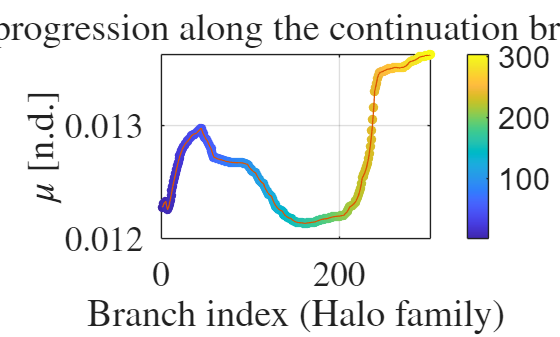

idx = 1:numel(branchToPlot.mu);

%% mu progression vs branch index
figure;
hold on;
grid on;
box on;

scatter(idx, branchToPlot.mu, 50, idx, 'filled');
plot(idx, branchToPlot.mu, '-', 'LineWidth', 1.0);

xlabel('Branch index (Halo family)');
ylabel('$\mu$ [n.d.]', 'Interpreter', 'latex');
title('$\mu$ progression along the continuation branch', 'Interpreter', 'latex');

cb = colorbar;
cb.Label.String = 'Branch index';
cb.Label.Interpreter = 'latex';

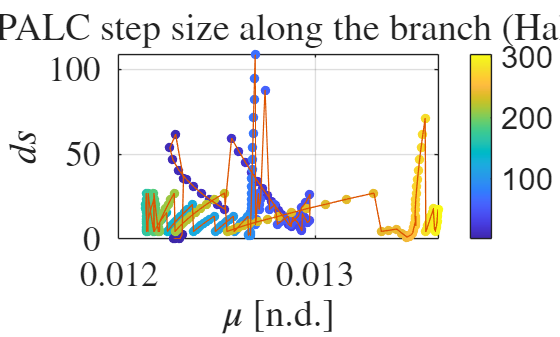



%% adaptive PALC step size vs mu, colored by branch index
figure;
hold on;
grid on;
box on;

scatter(branchToPlot.mu, branchToPlot.dsUsed, 50, idx, 'filled');
plot(branchToPlot.mu, branchToPlot.dsUsed, '-', 'LineWidth', 1.0);

xlabel('$\mu$ [n.d.]', 'Interpreter', 'latex');
ylabel('$ds$', 'Interpreter', 'latex');
title('Adaptive PALC step size along the branch (Halo family)', 'Interpreter', 'latex');

cb = colorbar;
cb.Label.String = 'Branch index';
cb.Label.Interpreter = 'latex';

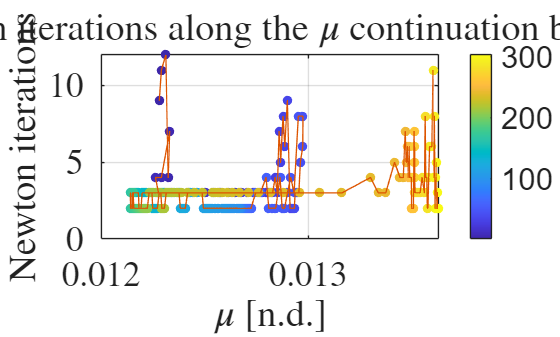



%% Newton iterations vs mu, colored by branch index
nB = numel(branchToPlot.info);
newtonIters = nan(nB,1);

for k = 1:nB
    if ~isempty(branchToPlot.info{k}) && isfield(branchToPlot.info{k}, 'normInf')
        newtonIters(k) = numel(branchToPlot.info{k}.normInf);
    end
end

figure;
hold on;
grid on;
box on;

scatter(branchToPlot.mu, newtonIters, 50, idx, 'filled');
plot(branchToPlot.mu, newtonIters, '-', 'LineWidth', 1.0);

xlabel('$\mu$ [n.d.]', 'Interpreter', 'latex');
ylabel('Newton iterations', 'Interpreter', 'latex');
title('Newton iterations along the $\mu$ continuation branch', 'Interpreter', 'latex');

cb = colorbar;
cb.Label.String = 'Branch index';
cb.Label.Interpreter = 'latex';

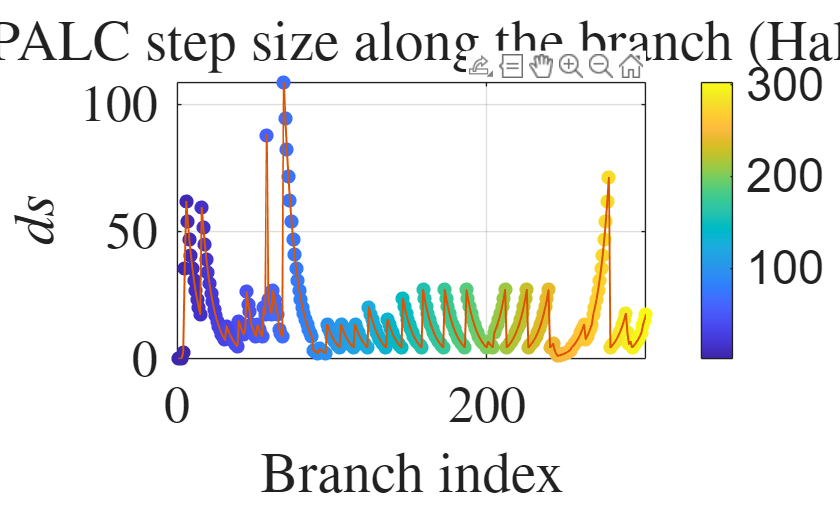



figure;
hold on;
grid on;
box on;

scatter(idx, branchToPlot.dsUsed, 50, idx, 'filled');
plot(idx, branchToPlot.dsUsed, '-', 'LineWidth', 1.0);

xlabel('Branch index');
ylabel('$ds$', 'Interpreter', 'latex');
title('Adaptive PALC step size along the branch  (Halo family)', 'Interpreter', 'latex');

cb = colorbar;
cb.Label.String = 'Branch index';
cb.Label.Interpreter = 'latex';

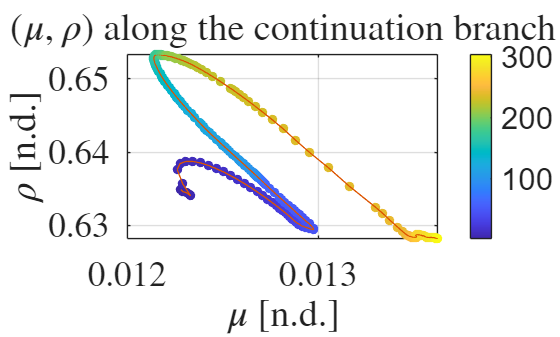

%% -------------------------
%  Choose which branch to plot
%  -------------------------
%
% Right now we plot the startup branch.
%branchToPlot = branchMaster0;

% If instead you want to plot the extended branch, use:
 branchToPlot = branchMaster;

%% -------------------------
%  Plot rho versus mu, colored by branch index
%  -------------------------
figure;
hold on;
grid on;
box on;

idx = 1:numel(branchToPlot.mu);

scatter(branchToPlot.mu, branchToPlot.rho, 50, idx, 'filled');
plot(branchToPlot.mu, branchToPlot.rho, '-', 'LineWidth', 1.0);

xlabel('$\mu$ [n.d.]');
ylabel('$\rho$ [n.d.]');
title('$(\mu,\rho)$ along the continuation branch');

cb = colorbar;
cb.Label.String = 'Branch index';
cb.Label.Interpreter = 'latex';

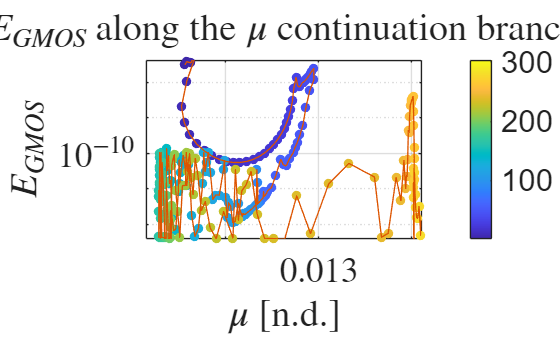


%% -------------------------
%  Plot EGMOS versus mu, colored by branch index
%  -------------------------
figure;
hold on;
grid on;
box on;

idx = 1:numel(branchToPlot.mu);

% Plot the points first so the color encodes branch order.
scatter(branchToPlot.mu, branchToPlot.EGMOS, 50, idx, 'filled');

% Use a standard line and then set the axis to log scale.
% This is cleaner than mixing scatter with semilogy.
plot(branchToPlot.mu, branchToPlot.EGMOS, '-', 'LineWidth', 1.0);
set(gca, 'YScale', 'log');

xlabel('$\mu$ [n.d.]');
ylabel('$E_{GMOS}$');
title('$E_{GMOS}$ along the $\mu$ continuation branch');

cb = colorbar;
cb.Label.String = 'Branch index';
cb.Label.Interpreter = 'latex';

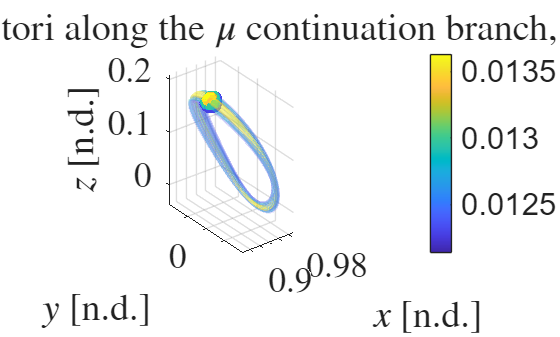

%% % ------------------------------------------------------------
% Plot selected full tori
% ------------------------------------------------------------


muAll  = branchMaster.mu(:);
rhoAll = branchMaster.rho(:);
nAll   = numel(muAll);

muMin = min(muAll);
muMax = max(muAll);
cmap  = parula(256);

% ------------------------------------------------------------
% Smart representative selection
% ------------------------------------------------------------
nShowBase = 15;   % number of roughly uniform-in-mu samples

muTargets = linspace(muMin, muMax, nShowBase);
idxMu = zeros(nShowBase,1);

for i = 1:nShowBase
    [~, idxMu(i)] = min(abs(muAll - muTargets(i)));
end

% Include endpoints
idxSpecial = [1; nAll];

% Include strongest bend in the (mu,rho) branch if possible
if nAll >= 4
    s1 = diff(rhoAll) ./ diff(muAll);
    bend = abs(diff(s1));
    [~, ib] = max(bend);
    idxSpecial(end+1) = ib + 1;
end

idxList = unique([idxSpecial; idxMu], 'stable');



%% % ------------------------------------------------------------
% Plot selected full tori
% ------------------------------------------------------------
figure;
ax = axes;
hold(ax, 'on');
grid(ax, 'on');
axis(ax, 'equal');
view(ax, 3);

for a = 1:numel(idxList)
    k = idxList(a);

    z_k  = branchMaster.z{k};
    mu_k = branchMaster.mu(k);

    cIdx = 1 + round((size(cmap,1)-1) * (mu_k - muMin) / max(muMax - muMin, eps));
    cIdx = max(1, min(size(cmap,1), cIdx));
    thisColor = cmap(cIdx,:);

    traj_k = gmos_propagate_qpos_orbits( ...
        z_k, N, mu_k, 1:3:N, 1, 600, ode_opts);

    style_k = struct( ...
        'mode', 'rgb', ...
        'rgb', thisColor, ...
        'alpha', 0.10, ...
        'lineWidth', 1.1, ...
        'newFigure', false, ...
        'ax', ax);

    gmos_plot_qpos_orbits_3d(traj_k, style_k, 0);
end

xlabel('$x$ [n.d.]');
ylabel('$y$ [n.d.]');
zlabel('$z$ [n.d.]');
title('Representative full tori along the $\mu$ continuation branch, colored by $\mu$');

colormap(ax, cmap);
caxis(ax, [muMin muMax]);
cb = colorbar(ax);
cb.Label.String = '$\mu$';
cb.Label.Interpreter = 'latex';

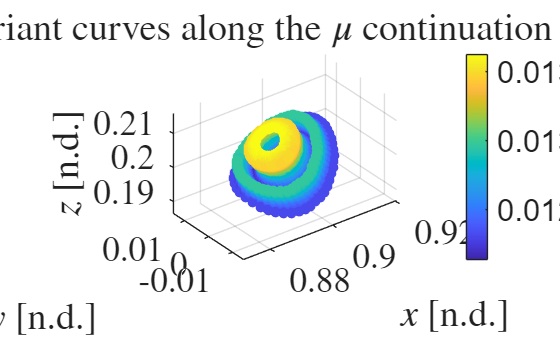

%% ------------------------------------------------------------
% Plot corresponding invariant curves for the same selected members
% ------------------------------------------------------------
figure;
ax2 = axes;
hold(ax2, 'on');
grid(ax2, 'on');
axis(ax2, 'equal');
view(ax2, 3);

for a = 1:numel(idxList)
    k = idxList(a);

    z_k  = branchMaster.z{k};
    mu_k = branchMaster.mu(k);

    [X0, ~, ~] = gmos_unpack_z(z_k, N);

    cIdx = 1 + round((size(cmap,1)-1) * (mu_k - muMin) / max(muMax - muMin, eps));
    cIdx = max(1, min(size(cmap,1), cIdx));
    thisColor = cmap(cIdx,:);

    scatter3(ax2, X0(1,:), X0(2,:), X0(3,:) , ...
        'Color', thisColor, ...
        'MarkerFaceColor', thisColor, ...
        'MarkerEdgeColor', thisColor, ...
        'LineWidth', 1.3 );
end

xlabel('$x$ [n.d.]');
ylabel('$y$ [n.d.]');
zlabel('$z$ [n.d.]');
title('Representative invariant curves along the $\mu$ continuation branch, colored by $\mu$');

colormap(ax2, cmap);
caxis(ax2, [muMin muMax]);
cb2 = colorbar(ax2);
cb2.Label.String = '$\mu$';
cb2.Label.Interpreter = 'latex';

%%%%%%%  Comparison with Nick;s KKG results, Halos

load('EarthMoon_SystemConstants_Nick')
load('L1_NorthernHaloFamily_Data_Nick')
load('DistantRetrograde_Family_Data_Nick')
load('L1_LyapunovFamily_Data_Nick') 

mu_EM_Nick=EMsys.mu

mu_EM_Nick = 0.0122

figure;
hold on
grid on
axis equal


% for i =1:1:250
orbit_number=81;

T_chosen=L1_NHalo_Fmly.t_hst(1,end,orbit_number);
X_chosen=L1_NHalo_Fmly.X_hst(1:6,1,orbit_number)

X_chosen =     0.8765
         0
    0.1920
         0
    0.2298
         0


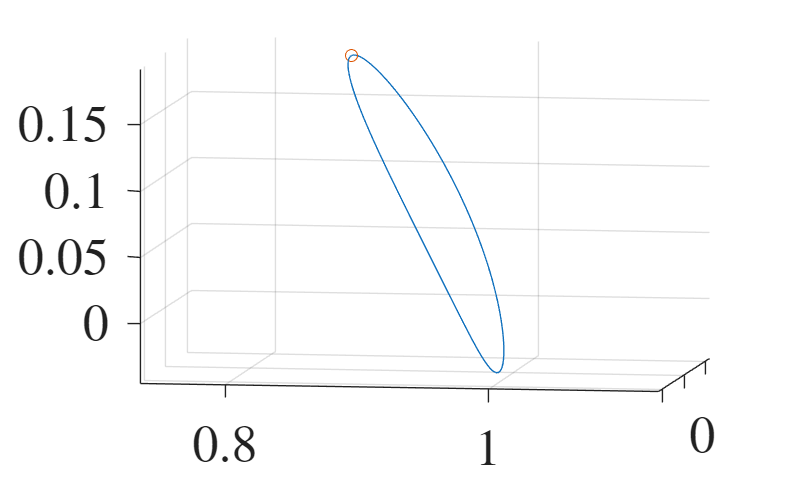

plot3(L1_NHalo_Fmly.X_hst(1,:,orbit_number),L1_NHalo_Fmly.X_hst(2,:,orbit_number),L1_NHalo_Fmly.X_hst(3,:,orbit_number))
scatter3(X_chosen(1),X_chosen(2),X_chosen(3))
view([9.138 6.140])


% end

% -------------------------------------------------
% -------------------------------------------------
% HALO TORUS FAMILY WITH FIXED JACOBI CONSTANT
% -------------------------------------------------

ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);

mu = mu_EM_Nick;
xPO0 = X_chosen(:);
TPO  = T_chosen;

mode = 'vertical';
N    = 51;

% Fixed Jacobi constant target from the chosen seed orbit
Ctarget = Jacobi_Constant(xPO0.', mu);

fprintf('Target Jacobi constant = %.16f\n', Ctarget);

Target Jacobi constant = 2.9980558801668300



% Two nearby seed amplitudes
K0 = 1e-7;
K1 = 2e-7;

demo0 = gmos_demo_invariance_only(mu, xPO0, TPO, N, K0, false, mode);

Mode: vertical
Eigenvector projections: planar 5.959e-01, vertical 8.031e-01
Init amplitude [x y z xd yd zd] = [2.29e-08 7.07e-08 1.30e-08 8.25e-08 4.31e-08 1.60e-07]
Max init amplitude: component 6, amp = 1.599e-07
Linearization test at j=1:
  ||dx0||      = 9.675e-08
  ||dx1||      = 6.692e-08
  ||dx1_lin||  = 6.692e-08
  ||dx1-dx1lin|| = 3.800e-12
Inf residual: +rho 2.357e-12, -rho 1.198e-07, using sign 1
||Finv||2   = 2.671e-11
||Finv||inf = 2.357e-12


demo1 = gmos_demo_invariance_only(mu, xPO0, TPO, N, K1, false, mode);

Mode: vertical
Eigenvector projections: planar 5.959e-01, vertical 8.031e-01
Init amplitude [x y z xd yd zd] = [4.58e-08 1.41e-07 2.60e-08 1.65e-07 8.62e-08 3.20e-07]
Max init amplitude: component 6, amp = 3.199e-07
Linearization test at j=1:
  ||dx0||      = 1.935e-07
  ||dx1||      = 1.338e-07
  ||dx1_lin||  = 1.338e-07
  ||dx1-dx1lin|| = 4.190e-12
Inf residual: +rho 2.626e-12, -rho 2.395e-07, using sign 1
||Finv||2   = 2.819e-11
||Finv||inf = 2.626e-12



init0 = demo0.init;
init1 = demo1.init;

% First reference for phase conditions
Xref   = init0.X0;
Tref   = init0.T0;
rhoref = init0.rho0;

z0 = gmos_pack_z(init0.X0, init0.T0, init0.rho0);
z1 = gmos_pack_z(init1.X0, init1.T0, init1.rho0);

optsN = struct();
optsN.maxIter = 16;
optsN.tolInf  = 1e-10;
optsN.verbose = true;

% Correct first seed with fixed C
[z0_sol, info0] = gmos_newton_fixC_analytic( ...
    z0, N, mu, Xref, Tref, rhoref, Ctarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 2.750e-12, ||F||2 = 3.044e-11



fprintf('seed 0 final ||F||inf = %.3e\n', info0.normInf(end));

seed 0 final ||F||inf = 2.750e-12



% Use corrected first seed as the reference for the second seed
[Xref1, Tref1, rhoref1] = gmos_unpack_z(z0_sol, N);

% Correct second seed with fixed C
[z1_sol, info1] = gmos_newton_fixC_analytic( ...
    z1, N, mu, Xref1, Tref1, rhoref1, Ctarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 3.015e-12, ||F||2 = 3.195e-11



fprintf('seed 1 final ||F||inf = %.3e\n', info1.normInf(end));

seed 1 final ||F||inf = 3.015e-12



% Check corrected seeds
[X0a, Ta, rhoa] = gmos_unpack_z(z0_sol, N);
[X0b, Tb, rhob] = gmos_unpack_z(z1_sol, N);

Ca = mean(Jacobi_Constant(X0a.', mu));
Cb = mean(Jacobi_Constant(X0b.', mu));

fprintf('seed 0: T = %.16f, rho = %.16f, mean(C) error = %.3e\n', ...
    Ta, rhoa, abs(Ca - Ctarget));

seed 0: T = 2.1708200810717755, rho = 0.8453522737222533, mean(C) error = 4.441e-15


fprintf('seed 1: T = %.16f, rho = %.16f, mean(C) error = %.3e\n', ...
    Tb, rhob, abs(Cb - Ctarget));

seed 1: T = 2.1708200810717755, rho = 0.8453522737222533, mean(C) error = 1.954e-14



% Continue the family with PALC at fixed C
ds     = 5e-4;   % try 1e-3 first; reduce if needed
nSteps = 200;

fam = gmos_continue_fixC_family_adaptive( ...
    z0_sol, z1_sol, nSteps, ds, N, mu, Ctarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 8.804e-08, ||F||2 = 6.165e-07
Newton iter  2: ||F||inf = 6.552e-14, ||F||2 = 4.480e-13
Continuation step 1/200: T = 2.170820130687436, rho = 0.845351760537102, Cavg = 2.998055880166830, ds = 5.000e-04, final ||F||inf = 6.552e-14
Newton iter  1: ||F||inf = 2.169e-07, ||F||2 = 1.518e-06
Newton iter  2: ||F||inf = 3.910e-13, ||F||2 = 2.698e-12
Continuation step 2/200: T = 2.170820309740594, rho = 0.845349906449556, Cavg = 2.998055880166828, ds = 5.750e-04, final ||F||inf = 3.910e-13
Newton iter  1: ||F||inf = 2.870e-07, ||F||2 = 2.008e-06
Newton iter  2: ||F||inf = 6.844e-13, ||F||2 = 4.709e-12
Continuation step 3/200: T = 2.170820677067804, rho = 0.845346103014419, Cavg = 2.998055880166827, ds = 6.612e-04, final ||F||inf = 6.844e-13
Newton iter  1: ||F||inf = 3.799e-07, ||F||2 = 2.655e-06
Newton iter  2: ||F||inf = 1.205e-12, ||F||2 = 8.241e-12
Continuation step 4/200: T = 2.170821312962473, rho = 0.845339519119283, Cavg = 2.998055880166823, ds = 7.604e-04, fin


%save('fam_fixC_halo_Nick_81.mat','fam')


extOpts = struct();
extOpts.tailSkip         = 10;   % skip suspicious tail points if needed
extOpts.deltaMuScale     = 0.15; % restart step scaling relative to local seed
extOpts.nSteps           = 12;   % short test extension
extOpts.saveFile         = 'fam_fixC_halo_Nick_81.mat';
extOpts.verbose          = true;
extOpts.continuationSide = 'tail';

load('fam_fixC_halo_Nick_81.mat')

fam=famMaster

fam = struct with fields:
          z: {40×1 cell}
        rho: [40×1 double]
          T: [40×1 double]
       Cavg: [40×1 double]
    normInf: [40×1 double]
       info: {40×1 cell}
    success: [40×1 logical]
     dsUsed: [40×1 double]



% [fam, meta] = gmos_extend_fixC_family_adaptive_bidirectional( ...
%     fam, N, mu, Ctarget, ode_opts, optsPALC, extOpts)
% if isfile(saveFile)
%     load(saveFile, 'fam');
%     fprintf('Loaded existing family from %s\n', saveFile);
% else
%     fam = gmos_continue_fixC_family( ...
%         z0_sol, z1_sol, nSteps, ds, N, mu, Ctarget, ode_opts, optsN);
%     save(saveFile, 'fam');
%     fprintf('Saved new family to %s\n', saveFile);
% end

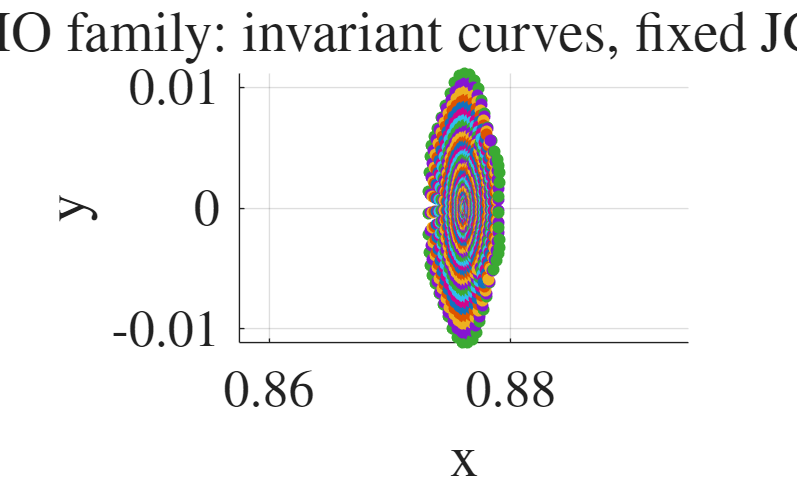


% Plot invariant curves from several family members
idxList = unique(round(linspace(1, numel(fam.z), min(105, numel(fam.z)))));

figure
hold on
grid on
axis equal
for ii = idxList(:).'
    [X0, ~, ~] = gmos_unpack_z(fam.z{ii}, N);
    scatter3(X0(1,:), X0(2,:), X0(3,:), 'filled')
end
xlabel('x')
ylabel('y')
zlabel('z')
title('NRHO family: invariant curves, fixed JC (GMOS)')

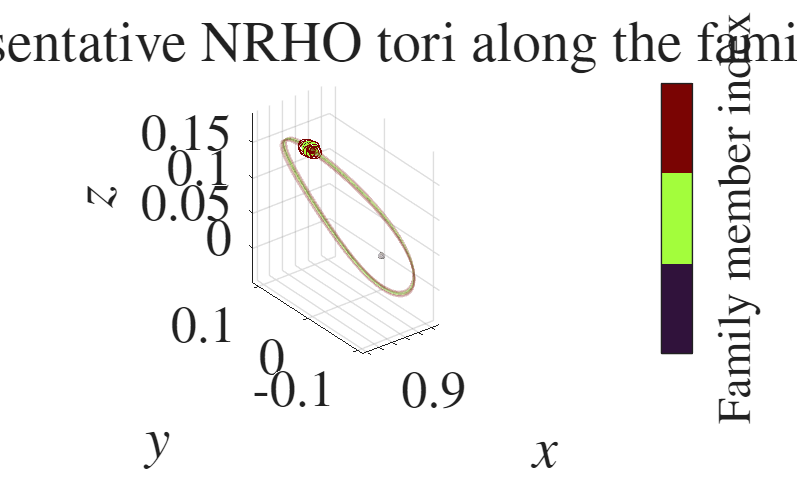

idxList = unique(round(linspace(1, numel(fam.z), 3)));
cmap = turbo(numel(idxList));

figure;
ax = axes;
hold(ax, 'on');
grid(ax, 'on');
axis(ax, 'equal');
view(ax, 3);

plot_Moon_nd(1e3,60,1);

for a = 1:numel(idxList)
    i = idxList(a);

    z = fam.z{i};

    traj = gmos_propagate_qpos_orbits( ...
        z, N, mu_EM_Nick, 1:5:N, 1, 300, ode_opts);

    style_i = struct( ...
        'mode', 'rgb', ...
        'rgb', cmap(a,:), ...
        'alpha', 0.1, ...
        'lineWidth', 1.0, ...
        'newFigure', false, ...
        'ax', ax);

    gmos_plot_qpos_orbits_3d(traj, style_i, 0);
end

xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');
title('Representative NRHO tori along the family','Interpreter','latex');

colormap(ax, cmap);
cb = colorbar(ax);
cb.Ticks = linspace(0,1,numel(idxList));
cb.TickLabels = string(idxList);
cb.Label.String = 'Family member index';
cb.Label.Interpreter = 'latex';

hold(ax, 'off');

%% ============================================================
% % Fixed-C family torus video
% % Precompute once, then render from cache
% % ============================================================
% 
% ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);
% 
% % -------------------------
% % Shared settings
% % -------------------------
% nShow = min(50, numel(fam.z));
% %idxList = unique(round(linspace(1, numel(fam.z), nShow)));
% u = linspace(0,1,nShow);
% idxList = unique(round(1 + (numel(fam.z)-1) * u.^1.5));
% 
% jList = 1:N;          % use all invariant-curve points
% nPeriods = 5;         % torus wrapping
% nSavePerPeriod = 600; % dense sampling along each trajectory
% 
% outFile = 'halo_tori_replace_HQ.mp4';
% 
% frameRate = 16;
% framesPerMember = 5;
% 
% cmap = turbo(numel(idxList));
% 
% % -------------------------
% % Precompute representative tori
% % -------------------------
% trajCache = cell(numel(idxList),1);
% 
% tic
% parfor a = 1:numel(idxList)
%     k = idxList(a);
%     z_k = fam.z{k};
% 
%     trajCache{a} = gmos_propagate_qpos_orbits( ...
%         z_k, N, mu_EM_Nick, jList, nPeriods, nSavePerPeriod, ode_opts);
% end
% toc
% 
% % Optional: save cache so you can rerender later without recomputing
% % save('halo_tori_cache_HQ.mat', 'trajCache', 'idxList', ...
% %      'jList', 'nPeriods', 'nSavePerPeriod', '-v7.3');
% 
% % -------------------------
% % Render video using cached trajectories
% % -------------------------
% v = VideoWriter(outFile, 'MPEG-4');
% v.FrameRate = frameRate;
% try
%     v.Quality = 100;
% end
% open(v);
% 
% fig = figure('Color','w', 'Renderer','opengl');
% fig.Position = [100 100 1600 1000];
% 
% ax = axes('Parent', fig);
% 
% for a = 1:numel(idxList)
%     k = idxList(a);
% 
%     cla(ax);
%     hold(ax, 'on');
%     grid(ax, 'on');
%     axis(ax, 'equal');
%     view(ax, 3);
%     camproj(ax, 'perspective');
% 
%     % USE THE CACHED TRAJECTORY
%     traj_k = trajCache{a};
%     thisColor = cmap(a,:);
% 
%     % Plot all strands directly into one axes
%     M = size(traj_k.Y, 3);
%     for m = 1:M
%         r = squeeze(traj_k.Y(1:3,:,m));
% 
%         patch(ax, ...
%             'XData', [r(1,:) nan], ...
%             'YData', [r(2,:) nan], ...
%             'ZData', [r(3,:) nan], ...
%             'FaceColor', 'none', ...
%             'EdgeColor', thisColor, ...
%             'EdgeAlpha', 0.12, ...
%             'LineWidth', 1.0);
%     end
% 
%     % Initial ring at t = 0
%     x_ring = squeeze(traj_k.Y(1,1,:));
%     y_ring = squeeze(traj_k.Y(2,1,:));
%     z_ring = squeeze(traj_k.Y(3,1,:));
% 
%     plot3(ax, x_ring, y_ring, z_ring, '-', ...
%         'Color', thisColor, ...
%         'LineWidth', 2.0);
% 
%     plot_Moon_nd(1e3, 60, 1);
% 
%     xlabel(ax, '$x$ [n.d.]', 'Interpreter', 'latex');
%     ylabel(ax, '$y$ [n.d.]', 'Interpreter', 'latex');
%     zlabel(ax, '$z$ [n.d.]', 'Interpreter', 'latex');
%     title(ax, sprintf('NRHO torus family, fixed JC (GMOS), member %d of %d', ...
%         k, numel(fam.z)), 'Interpreter', 'latex');
% 
%     set(ax, 'FontSize', 18);
% 
%     drawnow limitrate
% 
%     frame = getframe(fig);
%     for rep = 1:framesPerMember
%         writeVideo(v, frame);
%     end
% end
% 
% close(v);
% disp(['Saved video to ', outFile]);
% 
% beep

% %% ============================================================
% % Fixed-C family torus video
% % Precompute once, then render rotating video from cache
% % ============================================================
% 
% ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);
% 
% % -------------------------
% % Shared settings
% % -------------------------
% nShow = min(16, numel(fam.z));
% u = linspace(0,1,nShow);
% idxList = unique(round(1 + (numel(fam.z)-1) * u.^1.5));
% 
% jList = 1:N;          % use all invariant-curve points
% nPeriods = 5;         % keep this as requested
% nSavePerPeriod = 600; % dense sampling along each trajectory
% 
% outFile = 'halo_tori_rotation_HQ.mp4';
% 
% frameRate = 16;
% framesPerMember = 10;   % slower pacing
% 
% % Camera motion across the WHOLE movie
% nTurns = 1.0;           % at most one full turn total
% azStart = 25;
% elBase  = 18;
% elOscAmp = 2;           % much gentler elevation change
% 
% cmap = turbo(numel(idxList));
% 
% % -------------------------
% % Precompute representative tori
% % -------------------------
% trajCache = cell(numel(idxList),1);
% 
% tic
% parfor a = 1:numel(idxList)
%     k = idxList(a);
%     z_k = fam.z{k};
% 
%     trajCache{a} = gmos_propagate_qpos_orbits( ...
%         z_k, N, mu_EM_Nick, jList, nPeriods, nSavePerPeriod, ode_opts);
% end
% toc
% 
% % -------------------------
% % Compute fixed global axis limits from cache
% % -------------------------
% xAllMin = inf; xAllMax = -inf;
% yAllMin = inf; yAllMax = -inf;
% zAllMin = inf; zAllMax = -inf;
% 
% for a = 1:numel(trajCache)
%     Y = trajCache{a}.Y;
% 
%     X = Y(1,:,:); X = X(:);
%     Yv = Y(2,:,:); Yv = Yv(:);
%     Z = Y(3,:,:); Z = Z(:);
% 
%     xAllMin = min(xAllMin, min(X));
%     xAllMax = max(xAllMax, max(X));
%     yAllMin = min(yAllMin, min(Yv));
%     yAllMax = max(yAllMax, max(Yv));
%     zAllMin = min(zAllMin, min(Z));
%     zAllMax = max(zAllMax, max(Z));
% end
% 
% pad = 0.03;
% xLimFixed = [xAllMin-pad, xAllMax+pad];
% yLimFixed = [yAllMin-pad, yAllMax+pad];
% zLimFixed = [zAllMin-pad, zAllMax+pad];
% 
% % -------------------------
% % Render rotating video using cached trajectories
% % -------------------------
% v = VideoWriter(outFile, 'MPEG-4');
% v.FrameRate = frameRate;
% try
%     v.Quality = 100;
% end
% open(v);
% 
% fig = figure('Color','w', 'Renderer','opengl');
% fig.Position = [100 100 1600 1000];
% 
% ax = axes('Parent', fig);
% 
% nMembers = numel(idxList);
% totalFrames = nMembers * framesPerMember;
% azTotalSweep = 360 * nTurns;
% 
% for a = 1:nMembers
%     k = idxList(a);
% 
%     cla(ax);
%     hold(ax, 'on');
%     grid(ax, 'off');
%     box(ax, 'on');
%     axis(ax, 'manual');
%     axis(ax, 'equal');
%     daspect(ax, [1 1 1]);
%     camproj(ax, 'orthographic');
% 
%     xlim(ax, xLimFixed);
%     ylim(ax, yLimFixed);
%     zlim(ax, zLimFixed);
% 
%     traj_k = trajCache{a};
%     thisColor = cmap(a,:);
% 
%     % Plot all strands directly into one axes
%     M = size(traj_k.Y, 3);
%     for m = 1:M
%         r = squeeze(traj_k.Y(1:3,:,m));
% 
%         patch(ax, ...
%             'XData', [r(1,:) nan], ...
%             'YData', [r(2,:) nan], ...
%             'ZData', [r(3,:) nan], ...
%             'FaceColor', 'none', ...
%             'EdgeColor', thisColor, ...
%             'EdgeAlpha', 0.10, ...
%             'LineWidth', 0.9);
%     end
% 
%     % Initial ring at t = 0
%     x_ring = squeeze(traj_k.Y(1,1,:));
%     y_ring = squeeze(traj_k.Y(2,1,:));
%     z_ring = squeeze(traj_k.Y(3,1,:));
% 
%     plot3(ax, x_ring, y_ring, z_ring, '-', ...
%         'Color', thisColor, ...
%         'LineWidth', 1.8);
% 
%     plot_Moon_nd(1e3, 60, 1);
% 
%     xlabel(ax, '$x$ [n.d.]', 'Interpreter', 'latex');
%     ylabel(ax, '$y$ [n.d.]', 'Interpreter', 'latex');
%     zlabel(ax, '$z$ [n.d.]', 'Interpreter', 'latex');
%     title(ax, sprintf('NRHO torus family, fixed JC (GMOS), index %d', k), ...
%         'Interpreter', 'latex');
% 
%     set(ax, 'FontSize', 14);
% 
%     for f = 1:framesPerMember
%         globalFrame = (a - 1) * framesPerMember + f;
%         sGlobal = (globalFrame - 1) / max(totalFrames - 1, 1);
% 
%         az = azStart + azTotalSweep * sGlobal;
%         el = elBase + elOscAmp * sin(2*pi*sGlobal);
% 
%         view(ax, az, el);
%         drawnow limitrate
% 
%         frame = getframe(fig);
%         writeVideo(v, frame);
%     end
% end
% 
% close(v);
% disp(['Saved video to ', outFile]);
% 
% beep

%% Compute EGMOS and average Jacobi constant along the family

mu = mu_EM_Nick;   % or mu_EM_JPL, but be consistent everywhere

nFam = numel(fam.z);

EGMOS = nan(nFam,1);
Cavg  = nan(nFam,1);
Cmin  = nan(nFam,1);
Cmax  = nan(nFam,1);
Cspan = nan(nFam,1);
rho   = nan(nFam,1);
Tvals = nan(nFam,1);
xMax  = nan(nFam,1);
zMax  = nan(nFam,1);
Cerr_rms = nan(nFam,1); 

parfor k = 1:nFam
    z_k = fam.z{k};

    % GMOS midpoint accuracy metric
    [EGMOS(k), ~] = gmos_accuracy_test_paper(z_k, N, mu, ode_opts);

    % Unpack invariant curve and compute Jacobi values
    [X0_k, T_k, rho_k] = gmos_unpack_z(z_k, N);

    Cvals = Jacobi_Constant(X0_k.', mu);


    % RMS error relative to the target Jacobi constant
    Cerr_rms(k) = sqrt(mean((Cvals - Ctarget).^2));

    Cavg(k)  = mean(Cvals);
    Cmin(k)  = min(Cvals);
    Cmax(k)  = max(Cvals);
    Cspan(k) = Cmax(k) - Cmin(k);

    rho(k)   = rho_k;
    Tvals(k) = T_k;

    % Geometric parameters for horizontal and vertical axis
    xMax(k) = max(X0_k(1,:));
    zMax(k) = max(X0_k(3,:));
end

load('Halo81_QPO_Fam_Vals_Nick.mat')

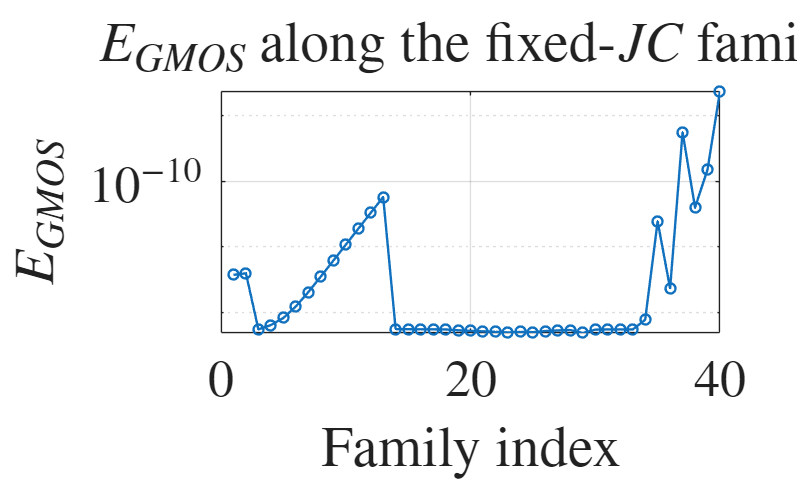

%% Plot EGMOS and average Jacobi constant vs family index

idx = (1:nFam).';

figure;
plot(idx, EGMOS, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);
set(gca, 'YScale', 'log');
grid on;
xlabel('Family index', 'Interpreter', 'latex');
ylabel('$E_{GMOS}$', 'Interpreter', 'latex');
title('$E_{GMOS}$ along the fixed-$JC$ family', 'Interpreter', 'latex');
hold off

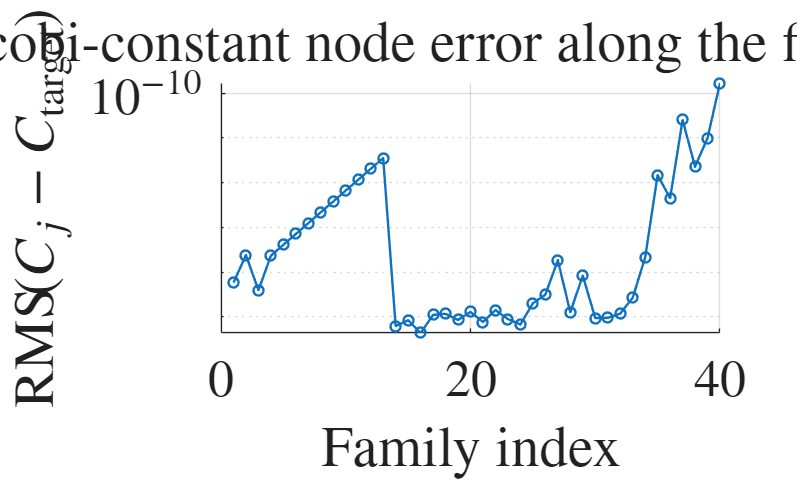


figure; hold on
plot(idx, Cerr_rms, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);



set(gca, 'YScale', 'log');
grid on;
xlabel('Family index', 'Interpreter', 'latex');
ylabel('$\mathrm{RMS}\!\left(C_j - C_{\mathrm{target}}\right)$', 'Interpreter', 'latex');
title('RMS Jacobi-constant node error along the fixed-$JC$ family', ...
    'Interpreter', 'latex');

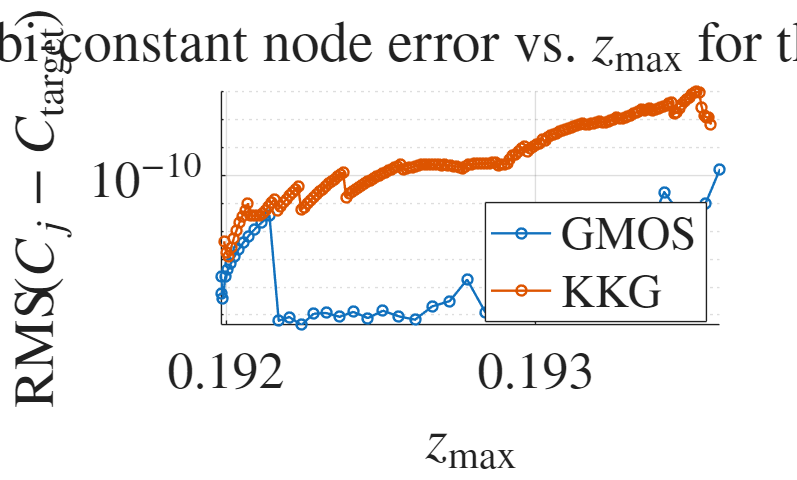

%% RMS Jacobi-constant node error: GMOS vs KKG for the DRO family

figure;
hold on;

plot(zMax, Cerr_rms, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'GMOS');

plot(Halo81_QPO_Fam_Vals.Z_PS_max_hst, Halo81_QPO_Fam_Vals.JC_errs, 'o-', ...
    'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'KKG');

set(gca, 'YScale', 'log');
grid on;
xlabel('$z_{\max}$', 'Interpreter', 'latex');
ylabel('$\mathrm{RMS}\!\left(C_j - C_{\mathrm{target}}\right)$', ...
    'Interpreter', 'latex');
title('RMS Jacobi-constant node error vs. $z_{\max}$ for the NRHO family', ...
    'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'best');

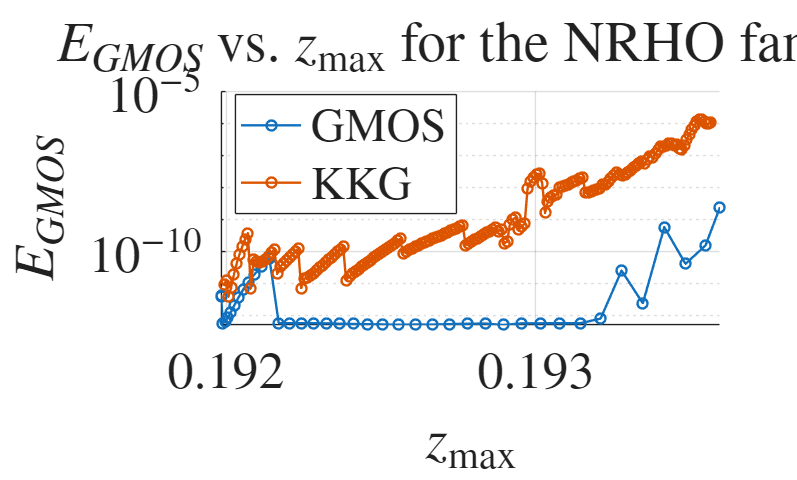



%% E_GMOS: GMOS vs KKG for the DRO family

figure;
hold on;

plot(zMax, EGMOS, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'GMOS');

plot(Halo81_QPO_Fam_Vals.Z_PS_max_hst, Halo81_QPO_Fam_Vals.GMOS_errs, 'o-', ...
    'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'KKG');

set(gca, 'YScale', 'log');
grid on;
xlabel('$z_{\max}$', 'Interpreter', 'latex');
ylabel('$E_{GMOS}$', 'Interpreter', 'latex');
title('$E_{GMOS}$ vs. $z_{\max}$ for the NRHO family', 'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'best');

Other Halo

figure;
hold on
grid on
axis equal


% for i =1:1:250
orbit_number=30;

T_chosen2=L1_NHalo_Fmly.t_hst(1,end,orbit_number);
X_chosen2=L1_NHalo_Fmly.X_hst(1:6,1,orbit_number)

X_chosen2 =     0.8260
         0
    0.0824
         0
    0.1964
         0


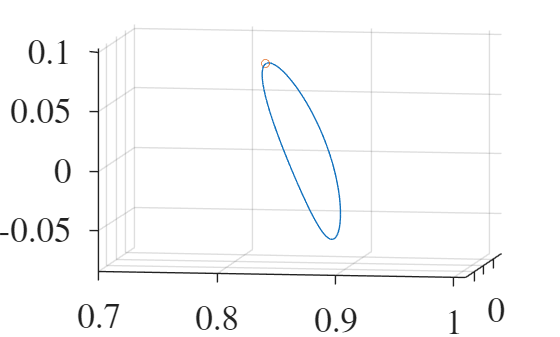

plot3(L1_NHalo_Fmly.X_hst(1,:,orbit_number),L1_NHalo_Fmly.X_hst(2,:,orbit_number),L1_NHalo_Fmly.X_hst(3,:,orbit_number))
scatter3(X_chosen2(1),X_chosen2(2),X_chosen2(3))
view([9.138 6.140])


% end

% -------------------------------------------------
% -------------------------------------------------
% HALO TORUS FAMILY WITH FIXED JACOBI CONSTANT
% -------------------------------------------------

ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);

mu = mu_EM_Nick;

Unrecognized function or variable 'mu_EM_Nick'.

xPO0 = X_chosen2(:);
TPO  = T_chosen2;

mode = 'vertical';
N    = 51;

% Fixed Jacobi constant target from the chosen seed orbit
Ctarget = Jacobi_Constant(xPO0.', mu);

fprintf('Target Jacobi constant = %.16f\n', Ctarget);

% Two nearby seed amplitudes
K0 = 1e-7;
K1 = 2e-7;

demo0 = gmos_demo_invariance_only(mu, xPO0, TPO, N, K0, false, mode);
demo1 = gmos_demo_invariance_only(mu, xPO0, TPO, N, K1, false, mode);

init0 = demo0.init;
init1 = demo1.init;

% First reference for phase conditions
Xref   = init0.X0;
Tref   = init0.T0;
rhoref = init0.rho0;

z0 = gmos_pack_z(init0.X0, init0.T0, init0.rho0);
z1 = gmos_pack_z(init1.X0, init1.T0, init1.rho0);

optsN = struct();
optsN.maxIter = 16;
optsN.tolInf  = 1e-10;
optsN.verbose = true;

% Correct first seed with fixed C
[z0_sol, info0] = gmos_newton_fixC_analytic( ...
    z0, N, mu, Xref, Tref, rhoref, Ctarget, ode_opts, optsN);

fprintf('seed 0 final ||F||inf = %.3e\n', info0.normInf(end));

% Use corrected first seed as the reference for the second seed
[Xref1, Tref1, rhoref1] = gmos_unpack_z(z0_sol, N);

% Correct second seed with fixed C
[z1_sol, info1] = gmos_newton_fixC_analytic( ...
    z1, N, mu, Xref1, Tref1, rhoref1, Ctarget, ode_opts, optsN);

fprintf('seed 1 final ||F||inf = %.3e\n', info1.normInf(end));

% Check corrected seeds
[X0a, Ta, rhoa] = gmos_unpack_z(z0_sol, N);
[X0b, Tb, rhob] = gmos_unpack_z(z1_sol, N);

Ca = mean(Jacobi_Constant(X0a.', mu));
Cb = mean(Jacobi_Constant(X0b.', mu));

fprintf('seed 0: T = %.16f, rho = %.16f, mean(C) error = %.3e\n', ...
    Ta, rhoa, abs(Ca - Ctarget));
fprintf('seed 1: T = %.16f, rho = %.16f, mean(C) error = %.3e\n', ...
    Tb, rhob, abs(Cb - Ctarget));


% Continue the family with PALC at fixed C
ds     = 1e-3;   % try 1e-3 first; reduce if needed
nSteps = 53;
% 
% fam = gmos_continue_fixC_family_adaptive( ...
%     z0_sol, z1_sol, nSteps, ds, N, mu, Ctarget, ode_opts, optsN);

fam_Halo_non_adaptive = gmos_continue_fixC_family( ...
     z0_sol, z1_sol, nSteps, ds, N, mu, Ctarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 7.511e-06, ||F||2 = 6.441e-05
Newton iter  2: ||F||inf = 4.640e-11, ||F||2 = 4.536e-10
Continuation step 1/53: T = 2.777856595740257, rho = 0.879198236207691, Cavg = 3.123390732197762, final ||F||inf = 4.640e-11
Newton iter  1: ||F||inf = 1.499e-05, ||F||2 = 1.286e-04
Newton iter  2: ||F||inf = 1.851e-10, ||F||2 = 1.808e-09
Newton iter  3: ||F||inf = 3.244e-13, ||F||2 = 1.056e-12
Continuation step 2/53: T = 2.777857210481210, rho = 0.879196007383670, Cavg = 3.123390732197764, final ||F||inf = 3.244e-13
Newton iter  1: ||F||inf = 1.500e-05, ||F||2 = 1.286e-04
Newton iter  2: ||F||inf = 1.852e-10, ||F||2 = 1.808e-09
Newton iter  3: ||F||inf = 2.723e-13, ||F||2 = 9.956e-13
Continuation step 3/53: T = 2.777858234915128, rho = 0.879192293646210, Cavg = 3.123390732197764, final ||F||inf = 2.723e-13
Newton iter  1: ||F||inf = 1.500e-05, ||F||2 = 1.286e-04
Newton iter  2: ||F||inf = 1.854e-10, ||F||2 = 1.808e-09
Newton iter  3: ||F||inf = 2.881e-13, ||F||2 = 8.991e-1


beep

 load('fam_fixC_halo_Nick_30.mat')

 fam=famMaster

fam = struct with fields:
          z: {53×1 cell}
        rho: [53×1 double]
          T: [53×1 double]
       Cavg: [53×1 double]
    normInf: [53×1 double]
       info: {53×1 cell}
    success: [53×1 logical]
     dsUsed: [53×1 double]


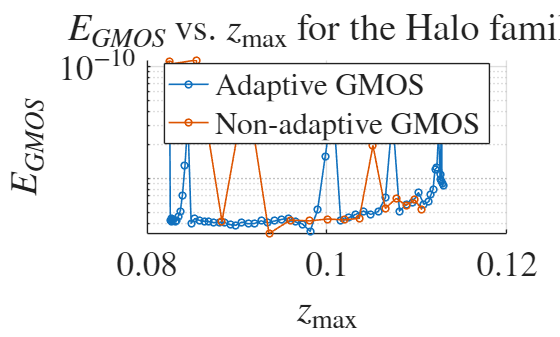

%% ============================================================
% Compare adaptive vs non-adaptive GMOS continuation
% Halo family, fixed JC
% ============================================================

mu = mu_EM_Nick;   % keep consistent
% Ctarget assumed already defined

%% -------------------------
% Adaptive family diagnostics
% -------------------------
nFam_ad = numel(fam.z);

EGMOS_ad    = nan(nFam_ad,1);
Cavg_ad     = nan(nFam_ad,1);
Cmin_ad     = nan(nFam_ad,1);
Cmax_ad     = nan(nFam_ad,1);
Cspan_ad    = nan(nFam_ad,1);
rho_ad      = nan(nFam_ad,1);
Tvals_ad    = nan(nFam_ad,1);
xMax_ad     = nan(nFam_ad,1);
zMax_ad     = nan(nFam_ad,1);
Cerr_rms_ad = nan(nFam_ad,1);

parfor k = 1:nFam_ad
    z_k = fam.z{k};

    % GMOS midpoint accuracy metric
    [EGMOS_ad(k), ~] = gmos_accuracy_test_paper(z_k, N, mu, ode_opts);

    % Unpack invariant curve and compute Jacobi values
    [X0_k, T_k, rho_k] = gmos_unpack_z(z_k, N);

    Cvals = Jacobi_Constant(X0_k.', mu);

    % RMS error relative to the target Jacobi constant
    Cerr_rms_ad(k) = sqrt(mean((Cvals - Ctarget).^2));

    Cavg_ad(k)  = mean(Cvals);
    Cmin_ad(k)  = min(Cvals);
    Cmax_ad(k)  = max(Cvals);
    Cspan_ad(k) = Cmax_ad(k) - Cmin_ad(k);

    rho_ad(k)   = rho_k;
    Tvals_ad(k) = T_k;

    % Geometric parameters
    xMax_ad(k) = max(X0_k(1,:));
    zMax_ad(k) = max(X0_k(3,:));   % use max(abs(...)) if that is your preferred definition
end

%% -------------------------
% Non-adaptive family diagnostics
% -------------------------
nFam_na = numel(fam_Halo_non_adaptive.z);

EGMOS_na    = nan(nFam_na,1);
Cavg_na     = nan(nFam_na,1);
Cmin_na     = nan(nFam_na,1);
Cmax_na     = nan(nFam_na,1);
Cspan_na    = nan(nFam_na,1);
rho_na      = nan(nFam_na,1);
Tvals_na    = nan(nFam_na,1);
xMax_na     = nan(nFam_na,1);
zMax_na     = nan(nFam_na,1);
Cerr_rms_na = nan(nFam_na,1);

parfor k = 1:nFam_na
    z_k = fam_Halo_non_adaptive.z{k};

    % GMOS midpoint accuracy metric
    [EGMOS_na(k), ~] = gmos_accuracy_test_paper(z_k, N, mu, ode_opts);

    % Unpack invariant curve and compute Jacobi values
    [X0_k, T_k, rho_k] = gmos_unpack_z(z_k, N);

    Cvals = Jacobi_Constant(X0_k.', mu);

    % RMS error relative to the target Jacobi constant
    Cerr_rms_na(k) = sqrt(mean((Cvals - Ctarget).^2));

    Cavg_na(k)  = mean(Cvals);
    Cmin_na(k)  = min(Cvals);
    Cmax_na(k)  = max(Cvals);
    Cspan_na(k) = Cmax_na(k) - Cmin_na(k);

    rho_na(k)   = rho_k;
    Tvals_na(k) = T_k;

    % Geometric parameters
    xMax_na(k) = max(X0_k(1,:));
    zMax_na(k) = max(X0_k(3,:));   % use max(abs(...)) if that is your preferred definition
end

%% -------------------------
% E_GMOS: adaptive vs non-adaptive
% -------------------------
figure;
hold on;

plot(zMax_ad, EGMOS_ad, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'Adaptive GMOS');

plot(zMax_na, EGMOS_na, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'Non-adaptive GMOS');

set(gca, 'YScale', 'log');
grid on;
xlabel('$z_{\max}$', 'Interpreter', 'latex');
ylabel('$E_{GMOS}$', 'Interpreter', 'latex');
title('$E_{GMOS}$ vs. $z_{\max}$ for the Halo family', 'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'best');

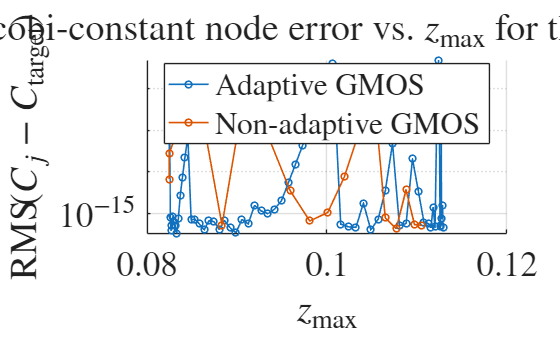


%% -------------------------
% RMS JC node error: adaptive vs non-adaptive
% -------------------------
figure;
hold on;

plot(zMax_ad, Cerr_rms_ad, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'Adaptive GMOS');

plot(zMax_na, Cerr_rms_na, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'Non-adaptive GMOS');

set(gca, 'YScale', 'log');
grid on;
xlabel('$z_{\max}$', 'Interpreter', 'latex');
ylabel('$\mathrm{RMS}\!\left(C_j - C_{\mathrm{target}}\right)$', ...
    'Interpreter', 'latex');
title('RMS Jacobi-constant node error vs. $z_{\max}$ for the Halo family', ...
    'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'best');

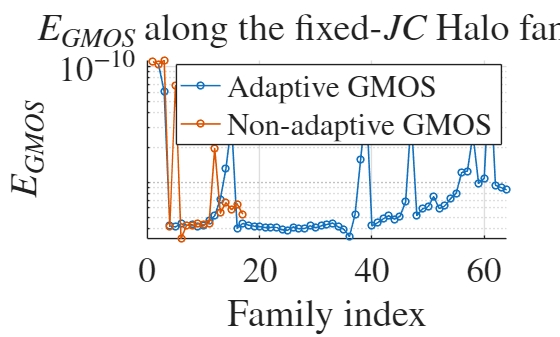


%% -------------------------
% Optional: same comparison vs family index
% -------------------------
idx_ad = (1:nFam_ad).';
idx_na = (1:nFam_na).';

figure;
hold on;
plot(idx_ad, EGMOS_ad, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'Adaptive GMOS');
plot(idx_na, EGMOS_na, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'Non-adaptive GMOS');
set(gca, 'YScale', 'log');
grid on;
xlabel('Family index', 'Interpreter', 'latex');
ylabel('$E_{GMOS}$', 'Interpreter', 'latex');
title('$E_{GMOS}$ along the fixed-$JC$ Halo family', 'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'best');

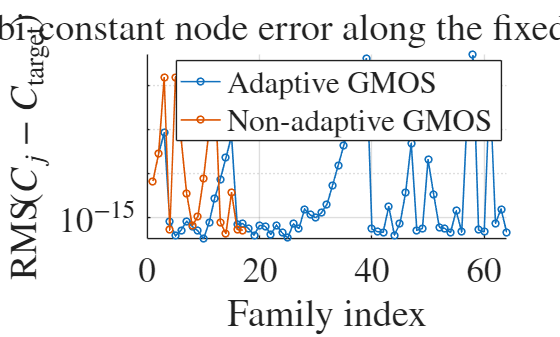


figure;
hold on;
plot(idx_ad, Cerr_rms_ad, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'Adaptive GMOS');
plot(idx_na, Cerr_rms_na, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'Non-adaptive GMOS');
set(gca, 'YScale', 'log');
grid on;
xlabel('Family index', 'Interpreter', 'latex');
ylabel('$\mathrm{RMS}\!\left(C_j - C_{\mathrm{target}}\right)$', ...
    'Interpreter', 'latex');
title('RMS Jacobi-constant node error along the fixed-$JC$ Halo family', ...
    'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'best');

extOpts = struct();
extOpts.tailSkip         = 1   % skip suspicious tail points if needed

extOpts = struct with fields:
    tailSkip: 1


extOpts.deltaMuScale     = 0.15; % restart step scaling relative to local seed
extOpts.nSteps           = 12;   % short test extension
extOpts.saveFile         = 'fam_fixC_halo_Nick_30.mat';
extOpts.verbose          = true;
extOpts.continuationSide = 'tail';

 

%fam=famMaster

[fam, meta] = gmos_extend_fixC_family_adaptive_bidirectional( ...
    fam, N, mu, Ctarget, ode_opts, optsPALC, extOpts)

Extending fixed-C family from the tail side
Using seed indices k0 = 51, k1 = 52
dsSeed   = 4.057691e-02
ds       = 4.057691e-02
Newton iter  1: ||F||inf = 4.617e-02, ||F||2 = 2.972e-01
Newton iter  2: ||F||inf = 1.545e-02, ||F||2 = 8.143e-02
Newton iter  3: ||F||inf = 7.944e-03, ||F||2 = 3.845e-02
Newton iter  4: ||F||inf = 5.424e-03, ||F||2 = 2.492e-02
Newton iter  5: ||F||inf = 3.250e-05, ||F||2 = 1.076e-04
Newton iter  6: ||F||inf = 2.997e-05, ||F||2 = 1.346e-04
Newton iter  7: ||F||inf = 1.067e-09, ||F||2 = 3.688e-09
Newton iter  8: ||F||inf = 3.782e-13, ||F||2 = 1.220e-12
Continuation step 1/12: T = 2.872924619232112, rho = 0.512413072056608, Cavg = 3.123390732197764, ds = 4.058e-02, final ||F||inf = 3.782e-13
Newton iter  1: ||F||inf = 5.395e-02, ||F||2 = 3.411e-01
Newton iter  2: ||F||inf = 2.584e-02, ||F||2 = 1.299e-01
Newton iter  3: ||F||inf = 1.421e-02, ||F||2 = 5.903e-02
Newton iter  4: ||F||inf = 2.771e-02, ||F||2 = 1.268e-01
Newton iter  5: ||F||inf = 1.027e-02, ||F||2 = 

fam = struct with fields:
          z: {64×1 cell}
        rho: [64×1 double]
          T: [64×1 double]
       Cavg: [64×1 double]
    normInf: [64×1 double]
       info: {64×1 cell}
    success: [64×1 logical]
     dsUsed: [64×1 double]


meta = struct with fields:
          side: 'tail'
       seedIdx: [51 52]
    skippedIdx: 53
       goodIdx: [53×1 double]
        dsSeed: 0.0406
            ds: 0.0406
          nOld: 53
      nSegment: 14
        nAdded: 12
          nNew: 64


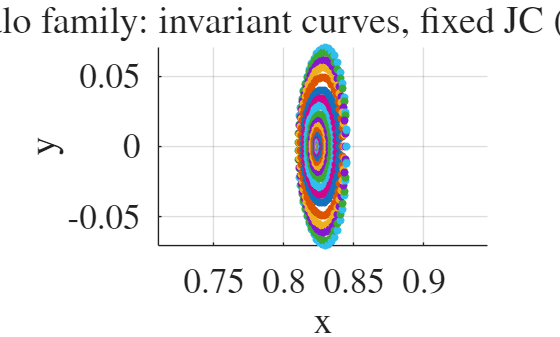


% Plot invariant curves from several family members
idxList = unique(round(linspace(1, numel(fam.z), min(20, numel(fam.z)))));

figure
hold on
grid on
axis equal
for ii = idxList(:).'
    [X0, ~, ~] = gmos_unpack_z(fam.z{ii}, N);
    scatter3(X0(1,:), X0(2,:), X0(3,:), 'filled')
end
xlabel('x')
ylabel('y')
zlabel('z')
title('Halo family: invariant curves, fixed JC (GMOS)')


beep

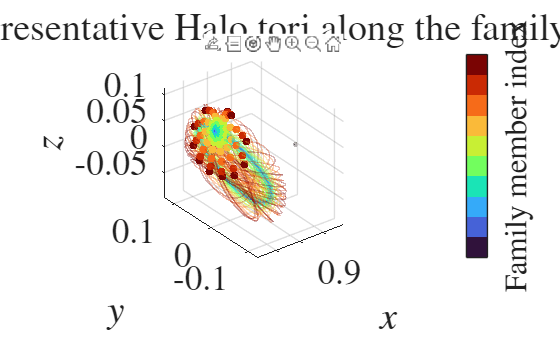

idxList = unique(round(linspace(1, numel(fam.z), 10)));
cmap = turbo(numel(idxList));

figure;
ax = axes;
hold(ax, 'on');
grid(ax, 'on');
axis(ax, 'equal');
view(ax, 3);

plot_Moon_nd(1e3,60,1);

for a = 1:numel(idxList)
    i = idxList(a);

    z = fam.z{i};

    traj = gmos_propagate_qpos_orbits( ...
        z, N, mu_EM_Nick, 1:5:N, 1, 200, ode_opts);

    style_i = struct( ...
        'mode', 'rgb', ...
        'rgb', cmap(a,:), ...
        'alpha', 0.3, ...
        'lineWidth', 1.0, ...
        'newFigure', false, ...
        'ax', ax);

    gmos_plot_qpos_orbits_3d(traj, style_i, 0);
end

xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');
title('Representative Halo tori along the family','Interpreter','latex');

colormap(ax, cmap);
cb = colorbar(ax);
cb.Ticks = linspace(0,1,numel(idxList));
cb.TickLabels = string(idxList);
cb.Label.String = 'Family member index';
cb.Label.Interpreter = 'latex';

hold(ax, 'off');

% Fixed-C family torus video
% Precompute once, then render from cache
% ============================================================

ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);

% -------------------------
% Shared settings
% -------------------------
nShow = min(50, numel(fam.z));
%idxList = unique(round(linspace(1, numel(fam.z), nShow)));
u = linspace(0,1,nShow);
idxList = unique(round(1 + (numel(fam.z)-1) * u.^1.5));

jList = 1:N;          % use all invariant-curve points
nPeriods = 1;         % torus wrapping
nSavePerPeriod = 600; % dense sampling along each trajectory

outFile = 'halo_tori__HQ.mp4';

frameRate = 16;
framesPerMember = 7;

cmap = turbo(numel(idxList));

% -------------------------
% Precompute representative tori
% -------------------------
trajCache = cell(numel(idxList),1);

tic
parfor a = 1:numel(idxList)
    k = idxList(a);
    z_k = fam.z{k};

    trajCache{a} = gmos_propagate_qpos_orbits( ...
        z_k, N, mu_EM_Nick, jList, nPeriods, nSavePerPeriod, ode_opts);
end
toc

Elapsed time is 0.921625 seconds.


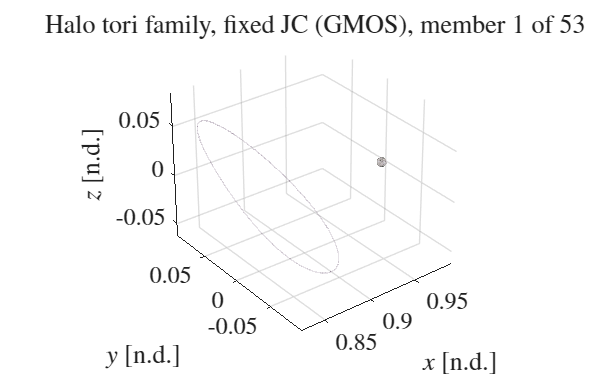

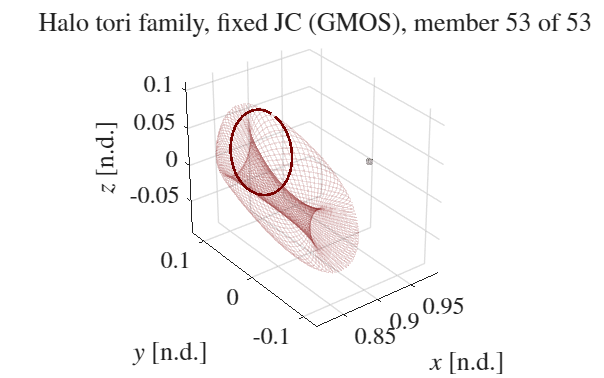


% Optional: save cache so you can rerender later without recomputing
% save('halo_tori_cache_HQ.mat', 'trajCache', 'idxList', ...
%      'jList', 'nPeriods', 'nSavePerPeriod', '-v7.3');

tic
% -------------------------
% Render video using cached trajectories
% -------------------------
v = VideoWriter(outFile, 'MPEG-4');
v.FrameRate = frameRate;
try
    v.Quality = 100;
end
open(v);

fig = figure('Color','w', 'Renderer','opengl');
fig.Position = [100 100 1600 1000];

ax = axes('Parent', fig);

for a = 1:numel(idxList)
    k = idxList(a);

    cla(ax);
    hold(ax, 'on');
    grid(ax, 'on');
    axis(ax, 'equal');
    view(ax, 3);
    camproj(ax, 'perspective');

    % USE THE CACHED TRAJECTORY
    traj_k = trajCache{a};
    thisColor = cmap(a,:);

    % Plot all strands directly into one axes
    M = size(traj_k.Y, 3);
    for m = 1:M
        r = squeeze(traj_k.Y(1:3,:,m));

        patch(ax, ...
            'XData', [r(1,:) nan], ...
            'YData', [r(2,:) nan], ...
            'ZData', [r(3,:) nan], ...
            'FaceColor', 'none', ...
            'EdgeColor', thisColor, ...
            'EdgeAlpha', 0.12, ...
            'LineWidth', 1.0);
    end

    % Initial ring at t = 0
    x_ring = squeeze(traj_k.Y(1,1,:));
    y_ring = squeeze(traj_k.Y(2,1,:));
    z_ring = squeeze(traj_k.Y(3,1,:));

    plot3(ax, x_ring, y_ring, z_ring, '-', ...
        'Color', thisColor, ...
        'LineWidth', 2.0);

    plot_Moon_nd(1e3, 60, 1);

    xlabel(ax, '$x$ [n.d.]', 'Interpreter', 'latex');
    ylabel(ax, '$y$ [n.d.]', 'Interpreter', 'latex');
    zlabel(ax, '$z$ [n.d.]', 'Interpreter', 'latex');
    title(ax, sprintf('Halo tori family, fixed JC (GMOS), member %d of %d', ...
        k, numel(fam.z)), 'Interpreter', 'latex');

    set(ax, 'FontSize', 18);

    drawnow limitrate

    frame = getframe(fig);
    for rep = 1:framesPerMember
        writeVideo(v, frame);
    end
end


close(v);
disp(['Saved video to ', outFile]);

Saved video to halo_tori__HQ.mp4


toc

Elapsed time is 143.825916 seconds.


beep

%% Compute EGMOS and average Jacobi constant along the family

mu = mu_EM_Nick;   % or mu_EM_JPL, but be consistent everywhere

nFam = numel(fam.z);

EGMOS = nan(nFam,1);
Cavg  = nan(nFam,1);
Cmin  = nan(nFam,1);
Cmax  = nan(nFam,1);
Cspan = nan(nFam,1);
rho   = nan(nFam,1);
Tvals = nan(nFam,1);
xMax  = nan(nFam,1);
zMax  = nan(nFam,1);
Cerr_rms = nan(nFam,1); 

parfor k = 1:nFam
    z_k = fam.z{k};

    % GMOS midpoint accuracy metric
    [EGMOS(k), ~] = gmos_accuracy_test_paper(z_k, N, mu, ode_opts);

    % Unpack invariant curve and compute Jacobi values
    [X0_k, T_k, rho_k] = gmos_unpack_z(z_k, N);

    Cvals = Jacobi_Constant(X0_k.', mu);


    % RMS error relative to the target Jacobi constant
    Cerr_rms(k) = sqrt(mean((Cvals - Ctarget).^2));

    Cavg(k)  = mean(Cvals);
    Cmin(k)  = min(Cvals);
    Cmax(k)  = max(Cvals);
    Cspan(k) = Cmax(k) - Cmin(k);

    rho(k)   = rho_k;
    Tvals(k) = T_k;

    % Geometric parameters for horizontal and vertical axis
    xMax(k) = max(X0_k(1,:));
    zMax(k) = max(X0_k(3,:));
end

load('Halo30_QPO_Fam_Vals_Nick.mat')

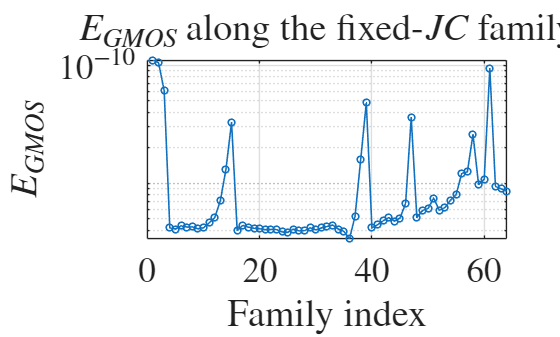

%% Plot EGMOS and average Jacobi constant vs family index

idx = (1:nFam).';

figure;
plot(idx, EGMOS, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);
set(gca, 'YScale', 'log');
grid on;
xlabel('Family index', 'Interpreter', 'latex');
ylabel('$E_{GMOS}$', 'Interpreter', 'latex');
title('$E_{GMOS}$ along the fixed-$JC$ family', 'Interpreter', 'latex');
hold off

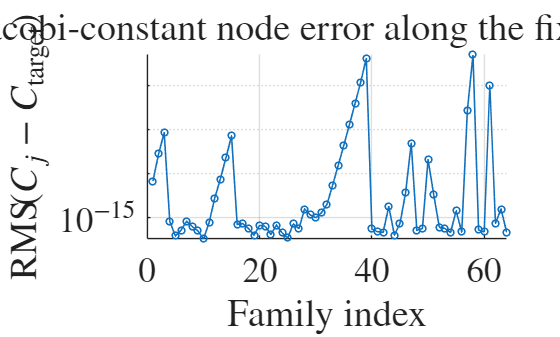


figure; hold on
plot(idx, Cerr_rms, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);



set(gca, 'YScale', 'log');
grid on;
xlabel('Family index', 'Interpreter', 'latex');
ylabel('$\mathrm{RMS}\!\left(C_j - C_{\mathrm{target}}\right)$', 'Interpreter', 'latex');
title('RMS Jacobi-constant node error along the fixed-$JC$ family', ...
    'Interpreter', 'latex');

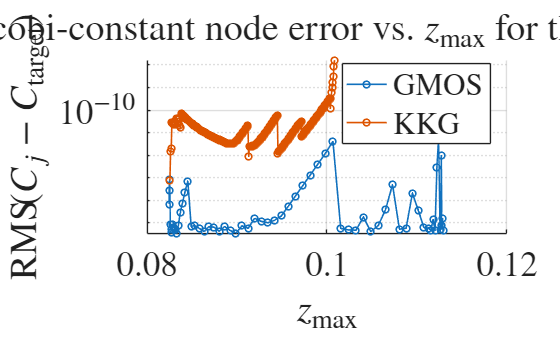


%% RMS Jacobi-constant node error: GMOS vs KKG for the DRO family

figure;
hold on;

plot(zMax, Cerr_rms, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'GMOS');

plot(Halo30_QPO_Fam_Vals.Z_PS_max_hst, Halo30_QPO_Fam_Vals.JC_errs, 'o-', ...
    'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'KKG');

set(gca, 'YScale', 'log');
grid on;
xlabel('$z_{\max}$', 'Interpreter', 'latex');
ylabel('$\mathrm{RMS}\!\left(C_j - C_{\mathrm{target}}\right)$', ...
    'Interpreter', 'latex');
title('RMS Jacobi-constant node error vs. $z_{\max}$ for the Halo family', ...
    'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'best');

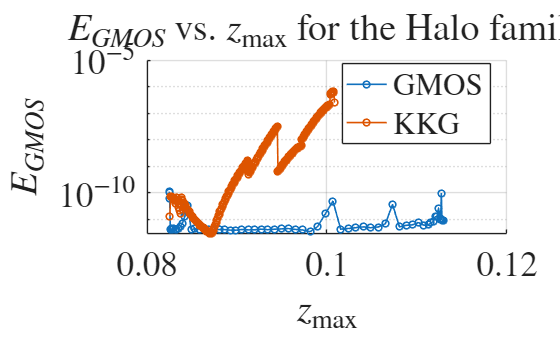



%% E_GMOS: GMOS vs KKG for the Halo family

figure;
hold on;

plot(zMax, EGMOS, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'GMOS');

plot(Halo30_QPO_Fam_Vals.Z_PS_max_hst, Halo30_QPO_Fam_Vals.GMOS_errs, 'o-', ...
    'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'KKG');

set(gca, 'YScale', 'log');
grid on;
xlabel('$z_{\max}$', 'Interpreter', 'latex');
ylabel('$E_{GMOS}$', 'Interpreter', 'latex');
title('$E_{GMOS}$ vs. $z_{\max}$ for the Halo family', 'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'best');

DRO

figure;
hold on
grid on
axis equal


% for i =1:1:250
orbit_number=150;

T_chosen3=DRO_Fmly.t_hst(1,end,orbit_number)

T_chosen3 = 5.9287

X_chosen3=DRO_Fmly.X_hst(1:6,1000,orbit_number)

X_chosen3 =     0.5183
   -0.0017
   -0.0000
    0.0009
    1.1487
   -0.0000


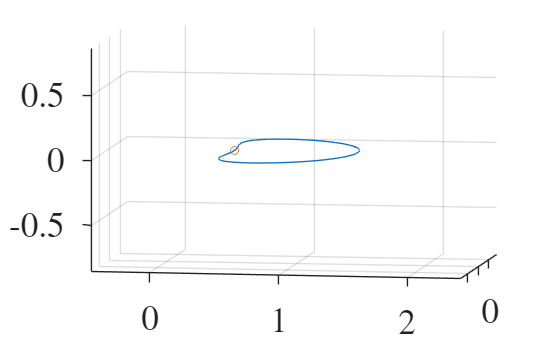

plot3(DRO_Fmly.X_hst(1,:,orbit_number),DRO_Fmly.X_hst(2,:,orbit_number),DRO_Fmly.X_hst(3,:,orbit_number))
scatter3(X_chosen3(1),X_chosen3(2),X_chosen3(3))
view([9.138 6.140])


% end

% -------------------------------------------------
% -------------------------------------------------
% DRO WITH FIXED JACOBI CONSTANT
% -------------------------------------------------

ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);

mu = mu_EM_Nick;
xPO0 = X_chosen3(:);
TPO  = T_chosen3;

mode = 'planar';
N    = 51;

% Fixed Jacobi constant target from the chosen seed orbit
Ctarget = Jacobi_Constant(xPO0.', mu);

fprintf('Target Jacobi constant = %.16f\n', Ctarget);

Target Jacobi constant = 2.7256700752362404



% Two nearby seed amplitudes
K0 = 1e-4;
K1 = 1.5e-4;

demo0 = gmos_demo_invariance_only(mu, xPO0, TPO, N, K0, false, mode);

Mode: planar
Eigenvector projections: planar 1.000e+00, vertical 2.151e-19
Init amplitude [x y z xd yd zd] = [7.67e-06 1.41e-04 4.30e-23 1.40e-04 1.96e-05 1.49e-28]
Max init amplitude: component 2, amp = 1.410e-04
Linearization test at j=1:
  ||dx0||      = 9.944e-05
  ||dx1||      = 1.079e-05
  ||dx1_lin||  = 1.067e-05
  ||dx1-dx1lin|| = 1.059e-06
Inf residual: +rho 7.698e-07, -rho 1.411e-04, using sign 1
||Finv||2   = 4.628e-06
||Finv||inf = 7.698e-07


demo1 = gmos_demo_invariance_only(mu, xPO0, TPO, N, K1, false, mode);

Mode: planar
Eigenvector projections: planar 1.000e+00, vertical 2.151e-19
Init amplitude [x y z xd yd zd] = [1.15e-05 2.12e-04 6.45e-23 2.10e-04 2.94e-05 2.23e-28]
Max init amplitude: component 2, amp = 2.115e-04
Linearization test at j=1:
  ||dx0||      = 1.492e-04
  ||dx1||      = 1.633e-05
  ||dx1_lin||  = 1.601e-05
  ||dx1-dx1lin|| = 2.383e-06
Inf residual: +rho 1.732e-06, -rho 2.117e-04, using sign 1
||Finv||2   = 1.041e-05
||Finv||inf = 1.732e-06



init0 = demo0.init;
init1 = demo1.init;

% First reference for phase conditions
Xref   = init0.X0;
Tref   = init0.T0;
rhoref = init0.rho0;

z0 = gmos_pack_z(init0.X0, init0.T0, init0.rho0);
z1 = gmos_pack_z(init1.X0, init1.T0, init1.rho0);

optsN = struct();
optsN.maxIter = 16;
optsN.tolInf  = 1e-10;
optsN.verbose = true;

% Correct first seed with fixed C
[z0_sol, info0] = gmos_newton_fixC_analytic( ...
    z0, N, mu, Xref, Tref, rhoref, Ctarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 7.698e-07, ||F||2 = 4.628e-06
Newton iter  2: ||F||inf = 8.373e-13, ||F||2 = 3.349e-12



fprintf('seed 0 final ||F||inf = %.3e\n', info0.normInf(end));

seed 0 final ||F||inf = 8.373e-13



% Use corrected first seed as the reference for the second seed
[Xref1, Tref1, rhoref1] = gmos_unpack_z(z0_sol, N);

% Correct second seed with fixed C
[z1_sol, info1] = gmos_newton_fixC_analytic( ...
    z1, N, mu, Xref1, Tref1, rhoref1, Ctarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 1.732e-06, ||F||2 = 1.041e-05
Newton iter  2: ||F||inf = 4.217e-12, ||F||2 = 1.695e-11



fprintf('seed 1 final ||F||inf = %.3e\n', info1.normInf(end));

seed 1 final ||F||inf = 4.217e-12



% Check corrected seeds
[X0a, Ta, rhoa] = gmos_unpack_z(z0_sol, N);
[X0b, Tb, rhob] = gmos_unpack_z(z1_sol, N);

Ca = mean(Jacobi_Constant(X0a.', mu));
Cb = mean(Jacobi_Constant(X0b.', mu));

fprintf('seed 0: T = %.16f, rho = %.16f, mean(C) error = %.3e\n', ...
    Ta, rhoa, abs(Ca - Ctarget));

seed 0: T = 5.9287111576007998, rho = 1.5882497875873081, mean(C) error = 0.000e+00


fprintf('seed 1: T = %.16f, rho = %.16f, mean(C) error = %.3e\n', ...
    Tb, rhob, abs(Cb - Ctarget));

seed 1: T = 5.9287111572576521, rho = 1.5882497934766611, mean(C) error = 8.882e-16


pi

ans = 3.1416

optsN = struct();
optsN.maxIter = 16;
optsN.tolInf  = 1e-10;
optsN.verbose = false;


% Continue the family with PALC at fixed C
ds     =1e-2;   % try 1e-3 first; reduce if needed
nSteps = 250;
% 

tic
% fam = gmos_continue_fixC_family_adaptive( ...
%     z0_sol, z1_sol, nSteps, ds, N, mu, Ctarget, ode_opts, optsN);

Continuation step 1/250: T = 5.928711033145730, rho = 1.588250076002288, Cavg = 2.725670075236240, ds = 1.000e-02, final ||F||inf = 7.148e-14
Continuation step 2/250: T = 5.928710623923979, rho = 1.588251029175028, Cavg = 2.725670075236192, ds = 1.150e-02, final ||F||inf = 2.645e-12
Continuation step 3/250: T = 5.928709800868545, rho = 1.588252946262852, Cavg = 2.725670075235752, ds = 1.322e-02, final ||F||inf = 2.735e-11
Continuation step 4/250: T = 5.928708388207745, rho = 1.588256236693887, Cavg = 2.725670075236225, ds = 1.521e-02, final ||F||inf = 8.237e-13
Continuation step 5/250: T = 5.928706147098879, rho = 1.588261456864300, Cavg = 2.725670075236240, ds = 1.749e-02, final ||F||inf = 9.323e-14
Continuation step 6/250: T = 5.928702754293946, rho = 1.588269359784880, Cavg = 2.725670075236240, ds = 2.011e-02, final ||F||inf = 8.276e-14
Continuation step 7/250: T = 5.928700408323291, rho = 1.588274824395066, Cavg = 2.725670075236226, ds = 1.157e-02, final ||F||inf = 7.950e-13
Contin

Continuation step 14/250: T = 5.928679105503801, rho = 1.588324450036399, Cavg = 2.725670075236226, ds = 7.691e-03, final ||F||inf = 9.146e-13
Continuation step 15/250: T = 5.928675731240379, rho = 1.588332311111055, Cavg = 2.725670075236220, ds = 8.845e-03, final ||F||inf = 1.145e-12
Continuation step 16/250: T = 5.928671641829848, rho = 1.588341838500297, Cavg = 2.725670075236222, ds = 1.017e-02, final ||F||inf = 1.068e-12
Continuation step 17/250: T = 5.928666662511163, rho = 1.588353439504614, Cavg = 2.725670075236176, ds = 1.170e-02, final ||F||inf = 3.684e-12
Continuation step 18/250: T = 5.928660570492394, rho = 1.588367633417892, Cavg = 2.725670075236240, ds = 1.345e-02, final ||F||inf = 6.634e-14
Continuation step 19/250: T = 5.928656890334142, rho = 1.588376208155881, Cavg = 2.725670075236224, ds = 7.735e-03, final ||F||inf = 9.652e-13
Continuation step 20/250: T = 5.928652498103814, rho = 1.588386442277995, Cavg = 2.725670075236219, ds = 8.895e-03, final ||F||inf = 1.285e-12

Continuation step 29/250: T = 5.928594331269823, rho = 1.588522000943803, Cavg = 2.725670075236221, ds = 7.823e-03, final ||F||inf = 1.167e-12
Continuation step 30/250: T = 5.928587845252654, rho = 1.588537119817276, Cavg = 2.725670075236213, ds = 8.996e-03, final ||F||inf = 1.620e-12
Continuation step 31/250: T = 5.928580168715277, rho = 1.588555014596966, Cavg = 2.725670075236216, ds = 1.035e-02, final ||F||inf = 1.426e-12
Continuation step 32/250: T = 5.928571052733502, rho = 1.588576266006402, Cavg = 2.725670075236155, ds = 1.190e-02, final ||F||inf = 5.133e-12
Continuation step 33/250: T = 5.928560188263492, rho = 1.588601595156058, Cavg = 2.725670075236241, ds = 1.368e-02, final ||F||inf = 6.867e-14
Continuation step 34/250: T = 5.928553756494209, rho = 1.588616590850118, Cavg = 2.725670075236218, ds = 7.867e-03, final ||F||inf = 1.367e-12
Continuation step 35/250: T = 5.928546193138556, rho = 1.588634225633165, Cavg = 2.725670075236210, ds = 9.047e-03, final ||F||inf = 1.905e-12

Continuation step 39/250: T = 5.928506823366825, rho = 1.588726034353455, Cavg = 2.725670075236214, ds = 7.912e-03, final ||F||inf = 1.579e-12
Continuation step 40/250: T = 5.928498161297832, rho = 1.588746237069659, Cavg = 2.725670075236203, ds = 9.099e-03, final ||F||inf = 2.305e-12
Continuation step 41/250: T = 5.928487975849513, rho = 1.588769994236568, Cavg = 2.725670075236210, ds = 1.046e-02, final ||F||inf = 1.947e-12
Continuation step 42/250: T = 5.928475966026842, rho = 1.588798008691804, Cavg = 2.725670075236135, ds = 1.203e-02, final ||F||inf = 6.605e-12
Continuation step 43/250: T = 5.928461762180944, rho = 1.588831143792238, Cavg = 2.725670075236240, ds = 1.384e-02, final ||F||inf = 8.617e-14
Continuation step 44/250: T = 5.928453404684474, rho = 1.588850641798938, Cavg = 2.725670075236209, ds = 7.957e-03, final ||F||inf = 1.962e-12
Continuation step 45/250: T = 5.928443621664718, rho = 1.588873466885196, Cavg = 2.725670075236193, ds = 9.150e-03, final ||F||inf = 2.891e-12

Continuation step 49/250: T = 5.928393368081759, rho = 1.588990738000107, Cavg = 2.725670075236202, ds = 8.002e-03, final ||F||inf = 2.374e-12
Continuation step 50/250: T = 5.928382440964194, rho = 1.589016242449238, Cavg = 2.725670075236181, ds = 9.202e-03, final ||F||inf = 3.731e-12
Continuation step 51/250: T = 5.928369643613547, rho = 1.589046114424590, Cavg = 2.725670075236199, ds = 1.058e-02, final ||F||inf = 2.701e-12
Continuation step 52/250: T = 5.928354620649197, rho = 1.589081184676397, Cavg = 2.725670075236108, ds = 1.217e-02, final ||F||inf = 8.607e-12
Continuation step 53/250: T = 5.928336939081700, rho = 1.589122465690505, Cavg = 2.725670075236240, ds = 1.400e-02, final ||F||inf = 7.066e-14
Continuation step 54/250: T = 5.928326575747497, rho = 1.589146663100594, Cavg = 2.725670075236193, ds = 8.047e-03, final ||F||inf = 3.096e-12
Continuation step 55/250: T = 5.928314480425031, rho = 1.589174906614825, Cavg = 2.725670075236162, ds = 9.255e-03, final ||F||inf = 5.037e-12

Continuation step 130/250: T = 5.926464874110016, rho = 1.593521314952013, Cavg = 2.725670075236240, ds = 5.037e-03, final ||F||inf = 6.217e-14
Continuation step 131/250: T = 5.926446019095539, rho = 1.593565912420578, Cavg = 2.725670075236240, ds = 5.793e-03, final ||F||inf = 5.482e-14
Continuation step 132/250: T = 5.926424229742481, rho = 1.593617457905102, Cavg = 2.725670075236240, ds = 6.662e-03, final ||F||inf = 8.633e-14
Continuation step 133/250: T = 5.926399031452424, rho = 1.593677077670167, Cavg = 2.725670075236232, ds = 7.661e-03, final ||F||inf = 9.844e-13
Continuation step 134/250: T = 5.926369867202284, rho = 1.593746094354974, Cavg = 2.725670075236240, ds = 8.811e-03, final ||F||inf = 8.144e-14
Continuation step 135/250: T = 5.926353007414566, rho = 1.593785999313913, Cavg = 2.725670075236240, ds = 5.066e-03, final ||F||inf = 6.325e-14
Continuation step 136/250: T = 5.926333536973572, rho = 1.593832089338106, Cavg = 2.725670075236240, ds = 5.826e-03, final ||F||inf = 5.

Continuation step 191/250: T = 5.924764830201079, rho = 1.597566860476236, Cavg = 2.725670075236241, ds = 6.200e-03, final ||F||inf = 8.242e-14
Continuation step 192/250: T = 5.924733026807564, rho = 1.597643019383058, Cavg = 2.725670075236240, ds = 7.130e-03, final ||F||inf = 8.402e-14
Continuation step 193/250: T = 5.924696270408397, rho = 1.597731061225637, Cavg = 2.725670075236239, ds = 8.200e-03, final ||F||inf = 1.498e-13
Continuation step 194/250: T = 5.924653758548176, rho = 1.597832918556765, Cavg = 2.725670075236236, ds = 9.430e-03, final ||F||inf = 1.215e-12
Continuation step 195/250: T = 5.924604548866277, rho = 1.597950863256367, Cavg = 2.725670075236240, ds = 1.084e-02, final ||F||inf = 4.896e-14
Continuation step 196/250: T = 5.924576097391593, rho = 1.598019074537692, Cavg = 2.725670075236241, ds = 6.236e-03, final ||F||inf = 7.927e-14
Continuation step 197/250: T = 5.924543237089568, rho = 1.598097873500152, Cavg = 2.725670075236240, ds = 7.171e-03, final ||F||inf = 8.

Continuation step 201/250: T = 5.924381109104402, rho = 1.598486934134112, Cavg = 2.725670075236240, ds = 6.271e-03, final ||F||inf = 1.039e-13
Continuation step 202/250: T = 5.924347163588131, rho = 1.598568452211164, Cavg = 2.725670075236240, ds = 7.212e-03, final ||F||inf = 7.107e-14
Continuation step 203/250: T = 5.924307934326262, rho = 1.598662684174215, Cavg = 2.725670075236240, ds = 8.293e-03, final ||F||inf = 8.515e-14
Continuation step 204/250: T = 5.924262566144295, rho = 1.598771696181348, Cavg = 2.725670075236237, ds = 9.537e-03, final ||F||inf = 8.338e-13
Continuation step 205/250: T = 5.924210055015548, rho = 1.598897916790933, Cavg = 2.725670075236240, ds = 1.097e-02, final ||F||inf = 1.232e-13
Continuation step 206/250: T = 5.924179697087312, rho = 1.598970910128613, Cavg = 2.725670075236240, ds = 6.307e-03, final ||F||inf = 1.130e-13
Continuation step 207/250: T = 5.924144636992649, rho = 1.599055229725146, Cavg = 2.725670075236240, ds = 7.253e-03, final ||F||inf = 8.

Continuation step 232/250: T = 5.922957087008808, rho = 1.601924178595677, Cavg = 2.725670075236240, ds = 7.461e-03, final ||F||inf = 6.295e-14
Continuation step 233/250: T = 5.922909216219241, rho = 1.602040355025799, Cavg = 2.725670075236241, ds = 8.580e-03, final ||F||inf = 4.119e-14
Continuation step 234/250: T = 5.922853864622915, rho = 1.602174737637931, Cavg = 2.725670075236239, ds = 9.867e-03, final ||F||inf = 2.295e-13
Continuation step 235/250: T = 5.922789811782988, rho = 1.602330313703032, Cavg = 2.725670075236239, ds = 1.135e-02, final ||F||inf = 9.858e-13
Continuation step 236/250: T = 5.922715621686637, rho = 1.602510603838482, Cavg = 2.725670075236237, ds = 1.305e-02, final ||F||inf = 3.886e-13
Continuation step 237/250: T = 5.922672705050065, rho = 1.602614941127666, Cavg = 2.725670075236240, ds = 7.503e-03, final ||F||inf = 7.874e-14
Continuation step 238/250: T = 5.922623117765466, rho = 1.602735537034766, Cavg = 2.725670075236240, ds = 8.629e-03, final ||F||inf = 5.

% 
% toc

Elapsed time is 574.899352 seconds.


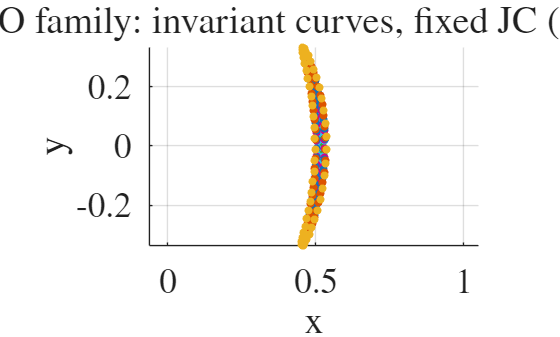


load('fam_fixC_DRO_Nick_150.mat','fam')


% if isfile(saveFile)
%     load(saveFile, 'fam');
%     fprintf('Loaded existing family from %s\n', saveFile);
% else
%     fam = gmos_continue_fixC_family( ...
%         z0_sol, z1_sol, nSteps, ds, N, mu, Ctarget, ode_opts, optsN);
%     save(saveFile, 'fam');
%     fprintf('Saved new family to %s\n', saveFile);
% end

% Plot invariant curves from several family members
idxList = unique(round(linspace(1, numel(fam.z), min(10, numel(fam.z)))));

figure
hold on
grid on
axis equal
for ii = idxList(:).'
    [X0, ~, ~] = gmos_unpack_z(fam.z{ii}, N);
    scatter3(X0(1,:), X0(2,:), X0(3,:), 'filled')
end
xlabel('x')
ylabel('y')
zlabel('z')
title('DRO family: invariant curves, fixed JC (GMOS)')


beep



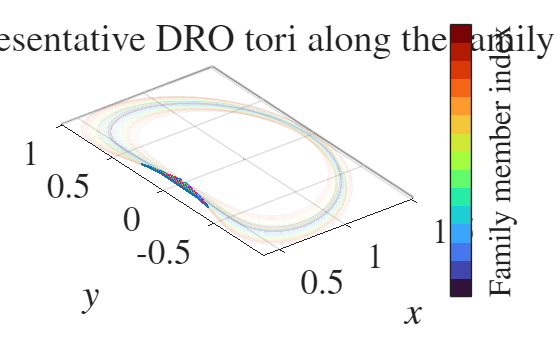

idxList = unique(round(linspace(1, numel(fam.z), 15)));
cmap = turbo(numel(idxList));

figure;
ax = axes;
hold(ax, 'on');
grid(ax, 'on');
axis(ax, 'equal');
view(ax, 3);

plot_Moon_nd(1e3,60,1);

for a = 1:numel(idxList)
    i = idxList(a);

    z = fam.z{i};

    traj = gmos_propagate_qpos_orbits( ...
        z, N, mu_EM_Nick, 1:10:N, 1, 300, ode_opts);

    style_i = struct( ...
        'mode', 'rgb', ...
        'rgb', cmap(a,:), ...
        'alpha', 0.04, ...
        'lineWidth', 1.0, ...
        'newFigure', false, ...
        'ax', ax);

    gmos_plot_qpos_orbits_3d(traj, style_i, 37);
end

xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');
title('Representative DRO tori along the family','Interpreter','latex');

colormap(ax, cmap);
cb = colorbar(ax);
cb.Ticks = linspace(0,1,numel(idxList));
cb.TickLabels = string(idxList);
cb.Label.String = 'Family member index';
cb.Label.Interpreter = 'latex';

hold(ax, 'off');

%% Compute EGMOS and average Jacobi constant along the family

mu = mu_EM_Nick;   % or mu_EM_JPL, but be consistent everywhere

nFam = numel(fam.z);

EGMOS = nan(nFam,1);
Cavg  = nan(nFam,1);
Cmin  = nan(nFam,1);
Cmax  = nan(nFam,1);
Cspan = nan(nFam,1);
rho   = nan(nFam,1);
Tvals = nan(nFam,1);
xMax  = nan(nFam,1);
Cerr_rms = nan(nFam,1); 

parfor k = 1:nFam
    z_k = fam.z{k};

    % GMOS midpoint accuracy metric
    [EGMOS(k), ~] = gmos_accuracy_test_paper(z_k, N, mu, ode_opts);

    % Unpack invariant curve and compute Jacobi values
    [X0_k, T_k, rho_k] = gmos_unpack_z(z_k, N);

    Cvals = Jacobi_Constant(X0_k.', mu);


    % RMS error relative to the target Jacobi constant
    Cerr_rms(k) = sqrt(mean((Cvals - Ctarget).^2));

    Cavg(k)  = mean(Cvals);
    Cmin(k)  = min(Cvals);
    Cmax(k)  = max(Cvals);
    Cspan(k) = Cmax(k) - Cmin(k);

    rho(k)   = rho_k;
    Tvals(k) = T_k;

    % Geometric parameter for horizontal axis
    xMax(k) = max(X0_k(1,:));
end

Starting parallel pool (parpool) using the 'Threads' profile ...
Connected to parallel pool with 6 workers.


load('DRO_QPO_Fam_Vals_Nick.mat')

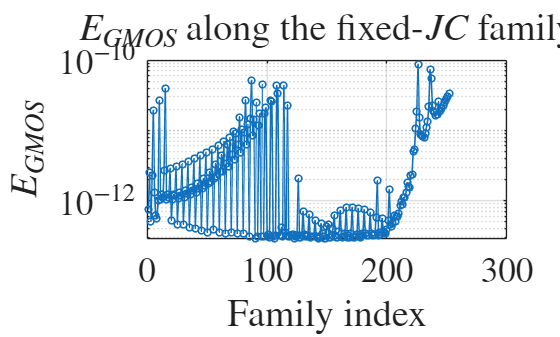

%% Plot EGMOS and average Jacobi constant vs family index

idx = (1:nFam).';

figure;
plot(idx, EGMOS, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);
set(gca, 'YScale', 'log');
grid on;
xlabel('Family index', 'Interpreter', 'latex');
ylabel('$E_{GMOS}$', 'Interpreter', 'latex');
title('$E_{GMOS}$ along the fixed-$JC$ family', 'Interpreter', 'latex');
hold off

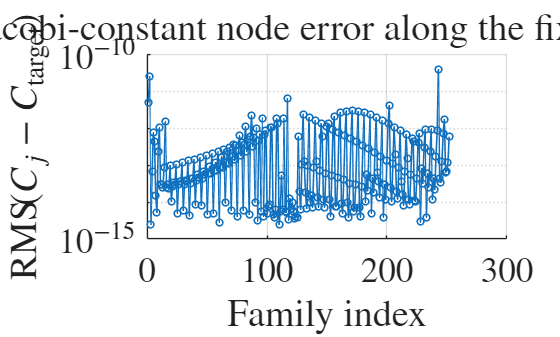


figure; hold on
plot(idx, Cerr_rms, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);



set(gca, 'YScale', 'log');
grid on;
xlabel('Family index', 'Interpreter', 'latex');
ylabel('$\mathrm{RMS}\!\left(C_j - C_{\mathrm{target}}\right)$', 'Interpreter', 'latex');
title('RMS Jacobi-constant node error along the fixed-$JC$ family', ...
    'Interpreter', 'latex');

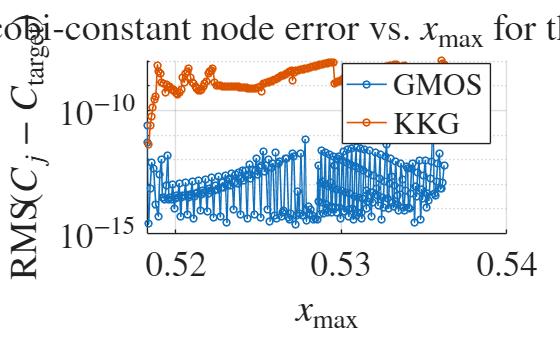

%% RMS Jacobi-constant node error: GMOS vs KKG for the DRO family

figure;
hold on;

plot(xMax, Cerr_rms, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'GMOS');

plot(DRO_QPO_Fam_Vals.X_PS_max_hst, DRO_QPO_Fam_Vals.JC_errs, 'o-', ...
    'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'KKG');

set(gca, 'YScale', 'log');
grid on;
xlabel('$x_{\max}$', 'Interpreter', 'latex');
ylabel('$\mathrm{RMS}\!\left(C_j - C_{\mathrm{target}}\right)$', ...
    'Interpreter', 'latex');
title('RMS Jacobi-constant node error vs. $x_{\max}$ for the DRO family', ...
    'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'best');

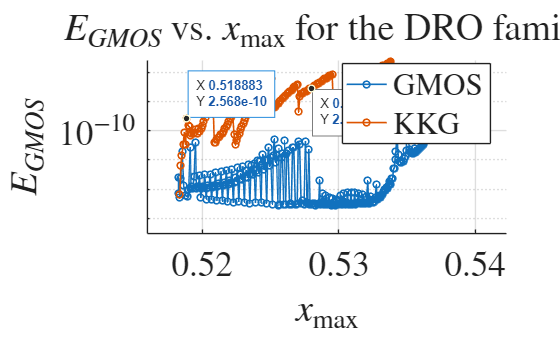



%% E_GMOS: GMOS vs KKG for the DRO family

figure;
hold on;

plot(xMax, EGMOS, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'GMOS');

plot(DRO_QPO_Fam_Vals.X_PS_max_hst, DRO_QPO_Fam_Vals.GMOS_errs, 'o-', ...
    'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'KKG');

set(gca, 'YScale', 'log');
grid on;
xlabel('$x_{\max}$', 'Interpreter', 'latex');
ylabel('$E_{GMOS}$', 'Interpreter', 'latex');
title('$E_{GMOS}$ vs. $x_{\max}$ for the DRO family', 'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'best');


% figure;
% plot(idx, Cavg, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);
% grid on;
% xlabel('Family index', 'Interpreter', 'latex');
% ylabel('$\overline{C}$', 'Interpreter', 'latex');
% title('Average Jacobi constant along the fixed-$JC$ family', 'Interpreter', 'latex');
% 
% figure;
% plot(idx, Cspan, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);
% set(gca, 'YScale', 'log');
% grid on;
% xlabel('Family index', 'Interpreter', 'latex');
% ylabel('$\max(C)-\min(C)$', 'Interpreter', 'latex');
% title('Jacobi spread along each invariant curve', 'Interpreter', 'latex');

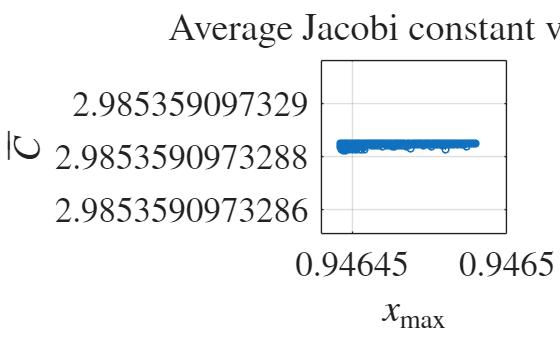


figure;
plot(xMax, Cavg, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);
grid on;
xlabel('$x_{\max}$', 'Interpreter', 'latex');
ylabel('$\overline{C}$', 'Interpreter', 'latex');
title('Average Jacobi constant vs. $x_{\max}$', 'Interpreter', 'latex');

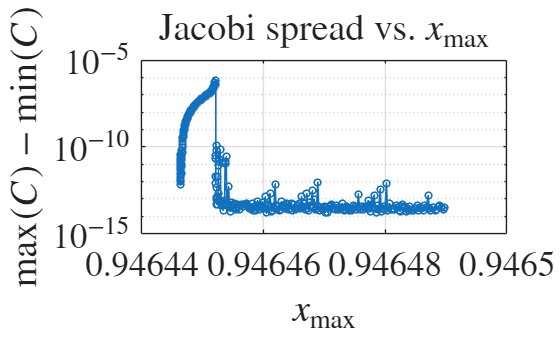


figure;
plot(xMax, Cspan, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);
set(gca, 'YScale', 'log');
grid on;
xlabel('$x_{\max}$', 'Interpreter', 'latex');
ylabel('$\max(C)-\min(C)$', 'Interpreter', 'latex');
title('Jacobi spread vs. $x_{\max}$', 'Interpreter', 'latex');

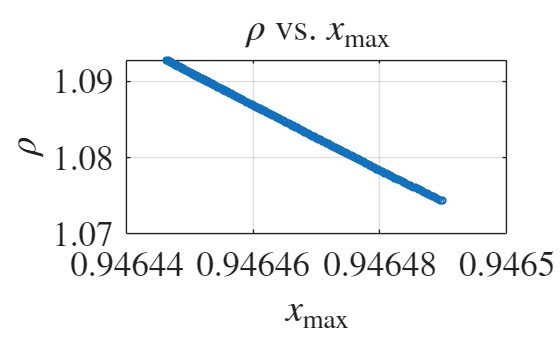


figure;
plot(xMax, rho, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);
grid on;
xlabel('$x_{\max}$', 'Interpreter', 'latex');
ylabel('$\rho$', 'Interpreter', 'latex');
title('$\rho$ vs. $x_{\max}$', 'Interpreter', 'latex');

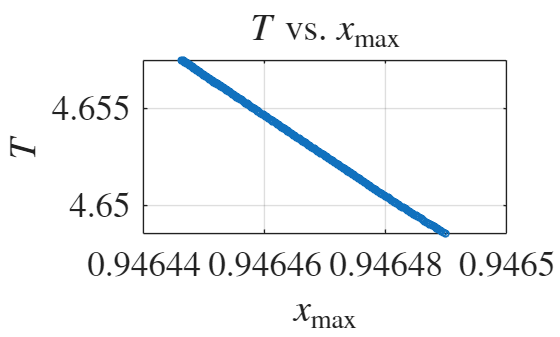


figure;
plot(xMax, Tvals, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);
grid on;
xlabel('$x_{\max}$', 'Interpreter', 'latex');
ylabel('$T$', 'Interpreter', 'latex');
title('$T$ vs. $x_{\max}$', 'Interpreter', 'latex');

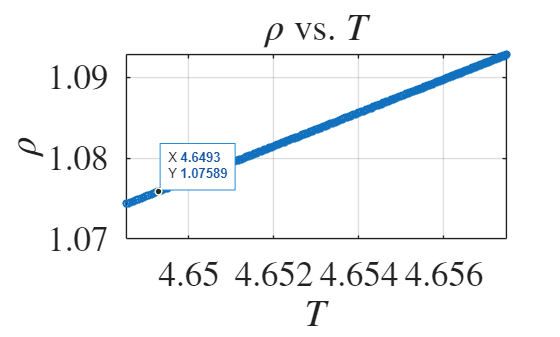


figure;
plot(Tvals, rho, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);
grid on;
xlabel('$T$', 'Interpreter', 'latex');
ylabel('$\rho$', 'Interpreter', 'latex');
title('$\rho$ vs. $T$', 'Interpreter', 'latex');

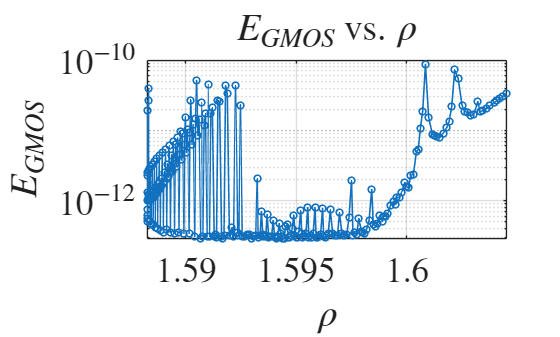


figure;
plot(rho, EGMOS, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);
set(gca, 'YScale', 'log');
grid on;
xlabel('$\rho$', 'Interpreter', 'latex');
ylabel('$E_{GMOS}$', 'Interpreter', 'latex');
title('$E_{GMOS}$ vs. $\rho$', 'Interpreter', 'latex');

Lyapunov

figure;
hold on
grid on
axis equal


% for i =1:1:250
orbit_number=80;

T_chosen4=L1_Lyap_Fmly.t_hst(1,end,orbit_number)

T_chosen4 = 4.6575

X_chosen4=L1_Lyap_Fmly.X_hst(1:6,1,orbit_number)

X_chosen4 =     0.7569
         0
    0.0000
         0
    0.5117
         0


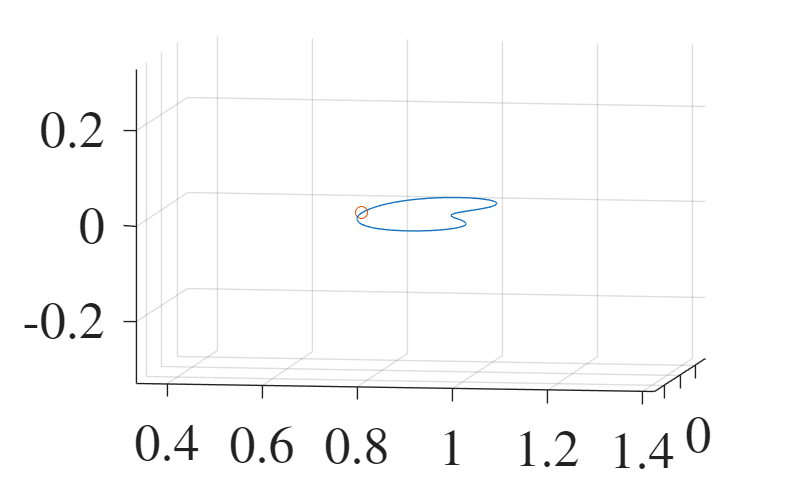

plot3(L1_Lyap_Fmly.X_hst(1,:,orbit_number),L1_Lyap_Fmly.X_hst(2,:,orbit_number),L1_Lyap_Fmly.X_hst(3,:,orbit_number))
scatter3(X_chosen4(1),X_chosen4(2),X_chosen4(3))
view([9.138 6.140])


% end

% -------------------------------------------------
% -------------------------------------------------
% Lyapunov WITH FIXED JACOBI CONSTANT
% -------------------------------------------------

ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);

mu = mu_EM_Nick;
xPO0 = X_chosen4(:);
TPO  = T_chosen4;

mode = 'vertical';
N    = 51;

% Fixed Jacobi constant target from the chosen seed orbit
Ctarget = Jacobi_Constant(xPO0.', mu);

fprintf('Target Jacobi constant = %.16f\n', Ctarget);

Target Jacobi constant = 2.9853590973288533



% Two nearby seed amplitudes
K0 = 1e-4;
K1 = 1.5e-4;

demo0 = gmos_demo_invariance_only(mu, xPO0, TPO, N, K0, false, mode);

Mode: vertical
Eigenvector projections: planar 3.425e-14, vertical 1.000e+00
Init amplitude [x y z xd yd zd] = [0.00e+00 6.06e-18 2.45e-05 3.04e-18 0.00e+00 1.98e-04]
Max init amplitude: component 6, amp = 1.983e-04
Linearization test at j=1:
  ||dx0||      = 9.924e-05
  ||dx1||      = 4.695e-05
  ||dx1_lin||  = 4.693e-05
  ||dx1-dx1lin|| = 1.288e-06
Inf residual: +rho 1.061e-06, -rho 1.762e-04, using sign 1
||Finv||2   = 5.632e-06
||Finv||inf = 1.061e-06


demo1 = gmos_demo_invariance_only(mu, xPO0, TPO, N, K1, false, mode);

Mode: vertical
Eigenvector projections: planar 3.425e-14, vertical 1.000e+00
Init amplitude [x y z xd yd zd] = [0.00e+00 9.10e-18 3.68e-05 4.56e-18 0.00e+00 2.97e-04]
Max init amplitude: component 6, amp = 2.974e-04
Linearization test at j=1:
  ||dx0||      = 1.489e-04
  ||dx1||      = 7.046e-05
  ||dx1_lin||  = 7.040e-05
  ||dx1-dx1lin|| = 2.904e-06
Inf residual: +rho 2.393e-06, -rho 2.643e-04, using sign 1
||Finv||2   = 1.271e-05
||Finv||inf = 2.393e-06



init0 = demo0.init;
init1 = demo1.init;

% First reference for phase conditions
Xref   = init0.X0;
Tref   = init0.T0;
rhoref = init0.rho0;

z0 = gmos_pack_z(init0.X0, init0.T0, init0.rho0);
z1 = gmos_pack_z(init1.X0, init1.T0, init1.rho0);

optsN = struct();
optsN.maxIter = 16;
optsN.tolInf  = 1e-10;
optsN.verbose = true;

% Correct first seed with fixed C
[z0_sol, info0] = gmos_newton_fixC_analytic( ...
    z0, N, mu, Xref, Tref, rhoref, Ctarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 1.061e-06, ||F||2 = 5.632e-06
Newton iter  2: ||F||inf = 3.877e-12, ||F||2 = 1.477e-11



fprintf('seed 0 final ||F||inf = %.3e\n', info0.normInf(end));

seed 0 final ||F||inf = 3.877e-12



% Use corrected first seed as the reference for the second seed
[Xref1, Tref1, rhoref1] = gmos_unpack_z(z0_sol, N);

% Correct second seed with fixed C
[z1_sol, info1] = gmos_newton_fixC_analytic( ...
    z1, N, mu, Xref1, Tref1, rhoref1, Ctarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 2.393e-06, ||F||2 = 1.271e-05
Newton iter  2: ||F||inf = 1.972e-11, ||F||2 = 7.487e-11



fprintf('seed 1 final ||F||inf = %.3e\n', info1.normInf(end));

seed 1 final ||F||inf = 1.972e-11



% Check corrected seeds
[X0a, Ta, rhoa] = gmos_unpack_z(z0_sol, N);
[X0b, Tb, rhob] = gmos_unpack_z(z1_sol, N);

Ca = mean(Jacobi_Constant(X0a.', mu));
Cb = mean(Jacobi_Constant(X0b.', mu));

fprintf('seed 0: T = %.16f, rho = %.16f, mean(C) error = %.3e\n', ...
    Ta, rhoa, abs(Ca - Ctarget));

seed 0: T = 4.6574778928810581, rho = 1.0928194000633782, mean(C) error = 1.332e-15


fprintf('seed 1: T = %.16f, rho = %.16f, mean(C) error = %.3e\n', ...
    Tb, rhob, abs(Cb - Ctarget));

seed 1: T = 4.6574778481328307, rho = 1.0928193074182384, mean(C) error = 0.000e+00


pi

ans = 3.1416

% Continue the family with PALC at fixed C
ds     =1e-3;   % try 1e-3 first; reduce if needed
nSteps = 200;
% 
fam = gmos_continue_fixC_family( ...
    z0_sol, z1_sol, nSteps, ds, N, mu, Ctarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 5.234e-06, ||F||2 = 2.782e-05
Newton iter  2: ||F||inf = 9.427e-11, ||F||2 = 3.583e-10
Continuation step 1/200: T = 4.657477495047599, rho = 1.092818575187644, Cavg = 2.985359097328851, final ||F||inf = 9.427e-11
Newton iter  1: ||F||inf = 8.359e-06, ||F||2 = 4.442e-05
Newton iter  2: ||F||inf = 2.404e-10, ||F||2 = 9.138e-10
Newton iter  3: ||F||inf = 1.992e-13, ||F||2 = 8.812e-13
Continuation step 2/200: T = 4.657476861319684, rho = 1.092817261273954, Cavg = 2.985359097328853, final ||F||inf = 1.992e-13
Newton iter  1: ||F||inf = 8.359e-06, ||F||2 = 4.442e-05
Newton iter  2: ||F||inf = 2.404e-10, ||F||2 = 9.138e-10
Newton iter  3: ||F||inf = 1.946e-13, ||F||2 = 8.952e-13
Continuation step 3/200: T = 4.657475946768158, rho = 1.092815365116270, Cavg = 2.985359097328853, final ||F||inf = 1.946e-13
Newton iter  1: ||F||inf = 8.359e-06, ||F||2 = 4.442e-05
Newton iter  2: ||F||inf = 2.404e-10, ||F||2 = 9.138e-10
Newton iter  3: ||F||inf = 2.373e-13, ||F||2 = 8.580


 tic
% fam = gmos_continue_fixC_family_adaptive( ...
%     z0_sol, z1_sol, nSteps, ds, N, mu, Ctarget, ode_opts, optsN);

toc

Elapsed time is 0.001295 seconds.


extOpts = struct();
extOpts.tailSkip         = 1;   % skip suspicious tail points if needed
extOpts.deltaMuScale     = 0.75; % restart step scaling relative to local seed
extOpts.nSteps           = 25;   % short test extension
extOpts.saveFile         = 'fam_fixC_Lyapunov_Nick_80_refined.mat';
extOpts.verbose          = true;
extOpts.continuationSide = 'tail';

 %save('fam_fixC_Lyapunov_Nick_80.mat', 'fam')

% [famLyapunov, meta] = gmos_extend_fixC_family_adaptive_bidirectional( ...
%     famLyapunov, N, mu, Ctarget, ode_opts, optsPALC, extOpts)


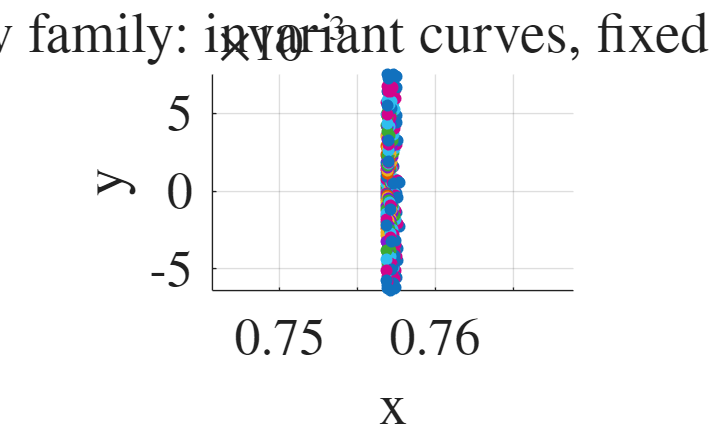


%fam=famMaster


% Plot invariant curves from several family members
idxList = unique(round(linspace(1, numel(fam.z), min(15, numel(fam.z)))));

figure
hold on
grid on
axis equal
for ii = idxList(:).'
    [X0, ~, ~] = gmos_unpack_z(fam.z{ii}, N);
    scatter3(X0(1,:), X0(2,:), X0(3,:), 'filled')
end
xlabel('x')
ylabel('y')
zlabel('z')
title('Lyapunov family: invariant curves, fixed JC (GMOS)')


beep



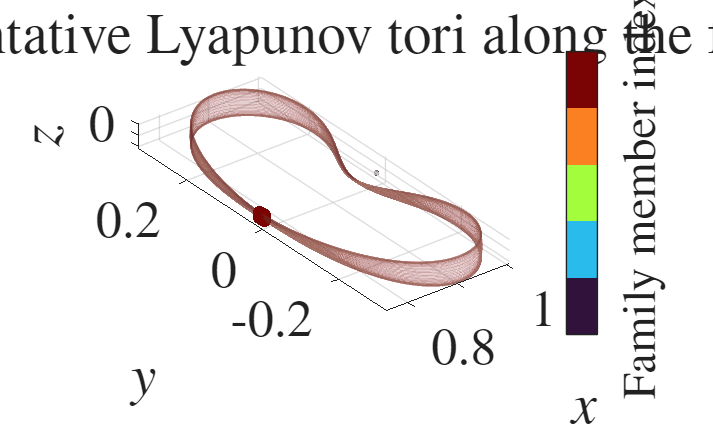

idxList = unique(round(linspace(1, numel(fam.z), 5)));
cmap = turbo(numel(idxList));

figure;
ax = axes;
hold(ax, 'on');
grid(ax, 'on');
axis(ax, 'equal');
view(ax, 3);

plot_Moon_nd(1e3,60,1);

for a = 1:numel(idxList)
    i = idxList(a);

    z = fam.z{end};

    traj = gmos_propagate_qpos_orbits( ...
        z, N, mu_EM_Nick, 1:1:N, 1, 800, ode_opts);

    style_i = struct( ...
        'mode', 'rgb', ...
        'rgb', cmap(a,:), ...
        'alpha', 0.1, ...
        'lineWidth', 1.0, ...
        'newFigure', false, ...
        'ax', ax);

    gmos_plot_qpos_orbits_3d(traj, style_i, 0);
end

xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');
title('Representative Lyapunov tori along the family','Interpreter','latex');

colormap(ax, cmap);
cb = colorbar(ax);
cb.Ticks = linspace(0,1,numel(idxList));
cb.TickLabels = string(idxList);
cb.Label.String = 'Family member index';
cb.Label.Interpreter = 'latex';

hold(ax, 'off');

%% Compute EGMOS and average Jacobi constant along the family

mu = mu_EM_Nick;   % or mu_EM_JPL, but be consistent everywhere

nFam = numel(fam.z);

EGMOS = nan(nFam,1);
Cavg  = nan(nFam,1);
Cmin  = nan(nFam,1);
Cmax  = nan(nFam,1);
Cspan = nan(nFam,1);
rho   = nan(nFam,1);
Tvals = nan(nFam,1);
xMax  = nan(nFam,1);
zMax  = nan(nFam,1);
Cerr_rms = nan(nFam,1); 

parfor k = 1:nFam
    z_k = fam.z{k};

    % GMOS midpoint accuracy metric
    [EGMOS(k), ~] = gmos_accuracy_test_paper(z_k, N, mu, ode_opts);

    % Unpack invariant curve and compute Jacobi values
    [X0_k, T_k, rho_k] = gmos_unpack_z(z_k, N);

    Cvals = Jacobi_Constant(X0_k.', mu);


    % RMS error relative to the target Jacobi constant
    Cerr_rms(k) = sqrt(mean((Cvals - Ctarget).^2));

    Cavg(k)  = mean(Cvals);
    Cmin(k)  = min(Cvals);
    Cmax(k)  = max(Cvals);
    Cspan(k) = Cmax(k) - Cmin(k);

    rho(k)   = rho_k;
    Tvals(k) = T_k;

    % Geometric parameters for horizontal and vertical axis
    xMax(k) = max(X0_k(1,:));
    zMax(k) = max(X0_k(3,:));
end

load('Lyap_QPO_Fam_Vals_Nick.mat')

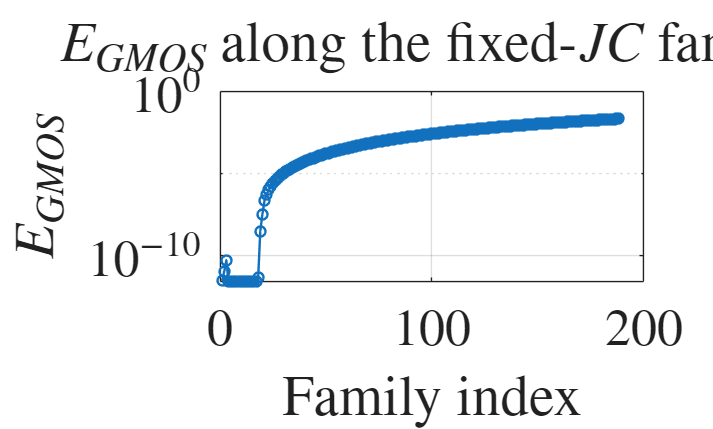

%% Plot EGMOS and average Jacobi constant vs family index

idx = (1:nFam).';

figure;
plot(idx, EGMOS, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);
set(gca, 'YScale', 'log');
grid on;
xlabel('Family index', 'Interpreter', 'latex');
ylabel('$E_{GMOS}$', 'Interpreter', 'latex');
title('$E_{GMOS}$ along the fixed-$JC$ family', 'Interpreter', 'latex');
hold off

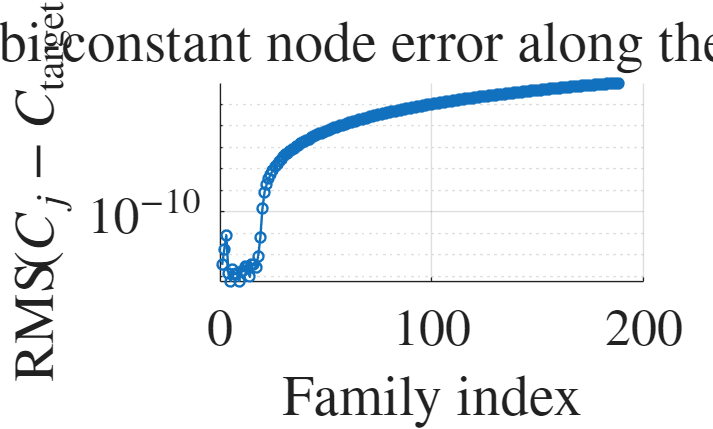


figure; hold on
plot(idx, Cerr_rms, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);



set(gca, 'YScale', 'log');
grid on;
xlabel('Family index', 'Interpreter', 'latex');
ylabel('$\mathrm{RMS}\!\left(C_j - C_{\mathrm{target}}\right)$', 'Interpreter', 'latex');
title('RMS Jacobi-constant node error along the fixed-$JC$ family', ...
    'Interpreter', 'latex');

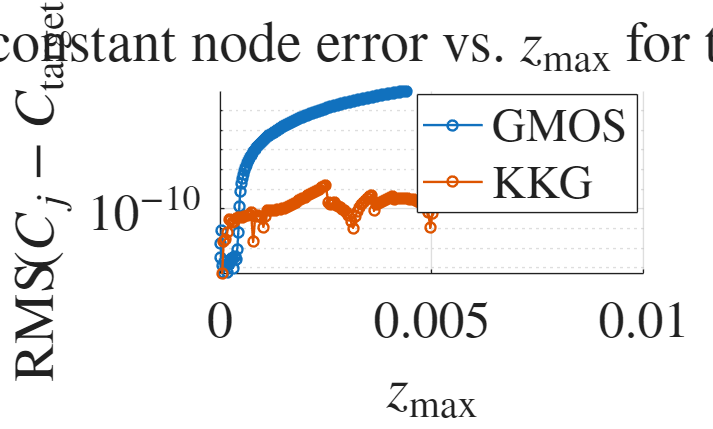

%% RMS Jacobi-constant node error: GMOS vs KKG for the DRO family

figure;
hold on;

plot(zMax, Cerr_rms, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'GMOS');

plot(Lyap_QPO_Fam_Vals.Z_PS_max_hst, Lyap_QPO_Fam_Vals.JC_errs, 'o-', ...
    'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'KKG');

set(gca, 'YScale', 'log');
grid on;
xlabel('$z_{\max}$', 'Interpreter', 'latex');
ylabel('$\mathrm{RMS}\!\left(C_j - C_{\mathrm{target}}\right)$', ...
    'Interpreter', 'latex');
title('RMS Jacobi-constant node error vs. $z_{\max}$ for the Lyapunov family', ...
    'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'best');

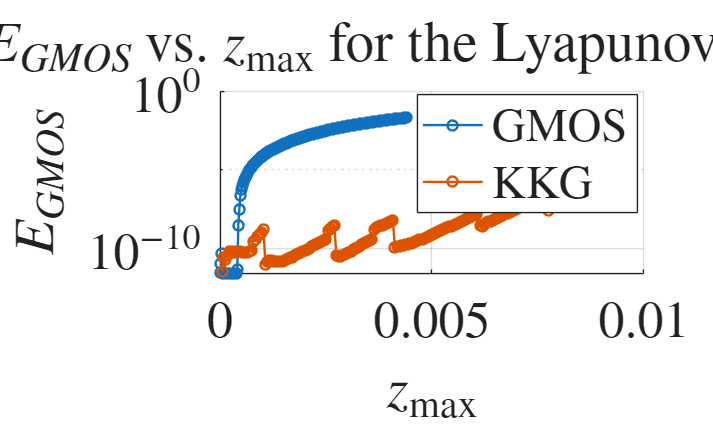



%% E_GMOS: GMOS vs KKG for the DRO family

figure;
hold on;

plot(zMax, EGMOS, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'GMOS');

plot(Lyap_QPO_Fam_Vals.Z_PS_max_hst, Lyap_QPO_Fam_Vals.GMOS_errs, 'o-', ...
    'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'KKG');

set(gca, 'YScale', 'log');
grid on;
xlabel('$z_{\max}$', 'Interpreter', 'latex');
ylabel('$E_{GMOS}$', 'Interpreter', 'latex');
title('$E_{GMOS}$ vs. $z_{\max}$ for the Lyapunov family', 'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'best');

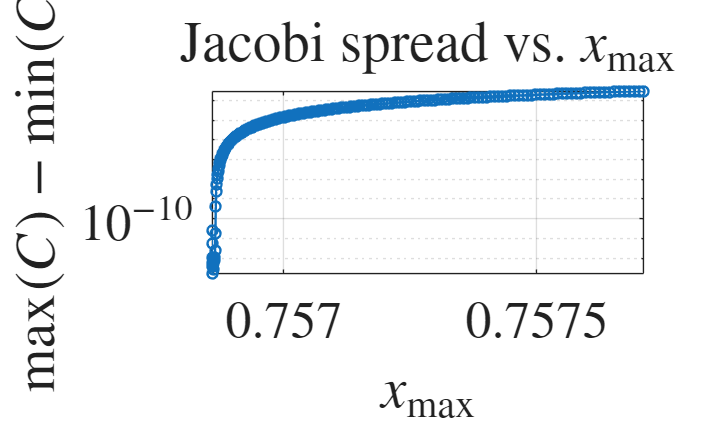

figure;
plot(xMax, Cspan, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);
set(gca, 'YScale', 'log');
grid on;
xlabel('$x_{\max}$', 'Interpreter', 'latex');
ylabel('$\max(C)-\min(C)$', 'Interpreter', 'latex');
title('Jacobi spread vs. $x_{\max}$', 'Interpreter', 'latex');

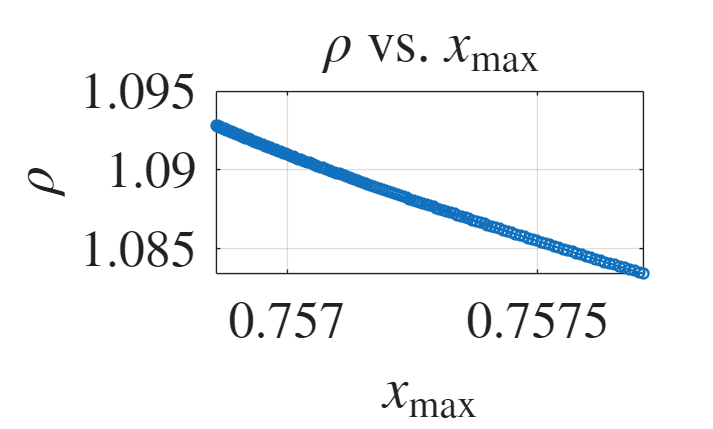


figure;
plot(xMax, rho, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);
grid on;
xlabel('$x_{\max}$', 'Interpreter', 'latex');
ylabel('$\rho$', 'Interpreter', 'latex');
title('$\rho$ vs. $x_{\max}$', 'Interpreter', 'latex');

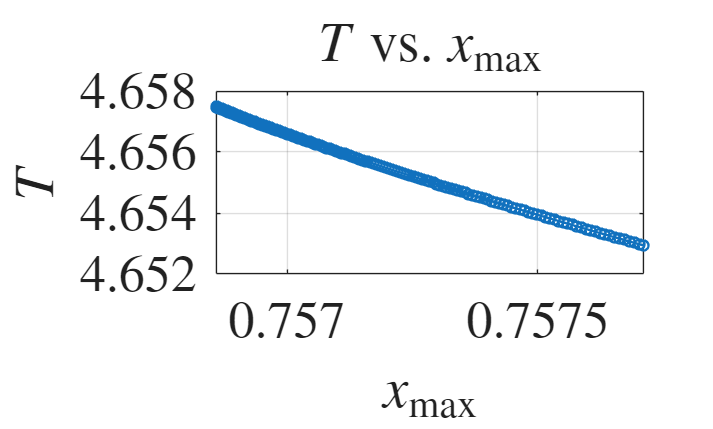


figure;
plot(xMax, Tvals, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);
grid on;
xlabel('$x_{\max}$', 'Interpreter', 'latex');
ylabel('$T$', 'Interpreter', 'latex');
title('$T$ vs. $x_{\max}$', 'Interpreter', 'latex');

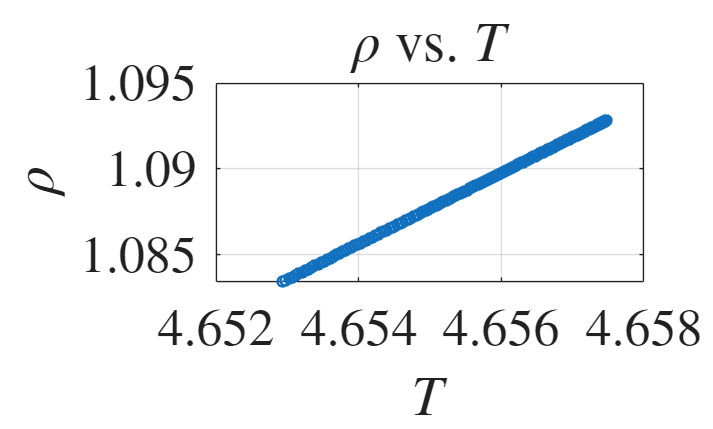


figure;
plot(Tvals, rho, 'o-', 'LineWidth', 1.2, 'MarkerSize', 5);
grid on;
xlabel('$T$', 'Interpreter', 'latex');
ylabel('$\rho$', 'Interpreter', 'latex');
title('$\rho$ vs. $T$', 'Interpreter', 'latex');


 save('fam_fixC_Lyapunov_Nick_80_constant.mat','fam_Lyap80_unrefined') 
% fam_Lyap80_unrefined=famMaster
 %save('fam_Lyap80_unrefined.mat', 'fam_Lyap80_unrefined')
save('fam_fixC_Lyapunov_Nick_80_adaptive.mat','fam_Lyap80_refined')
 % fam_Lyap80_refined=fam


 save('fam_fixC_Lyapunov_Nick_80_refined.mat', 'fam_Lyap80_refined')

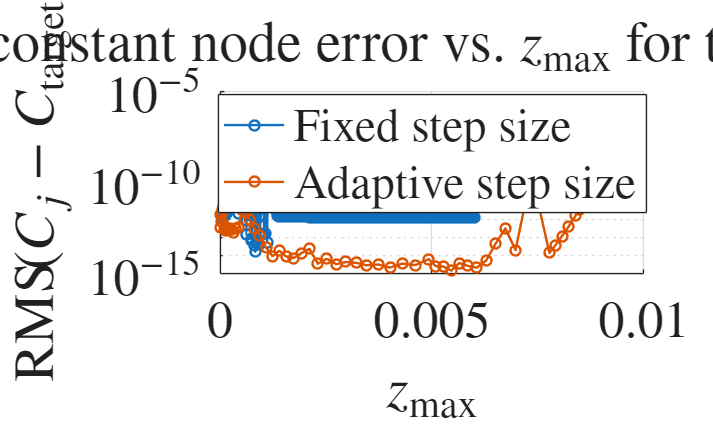

%% ============================================================
% Compare unrefined (fixed-step) vs refined (adaptive-step) GMOS
% for the Lyapunov QPO family
% ============================================================

mu = mu_EM_Nick;          % keep consistent with how the family was generated
N  = 51;                  % or your current N
Ctarget = Jacobi_Constant(xPO0.', mu);

%% -------------------------
% Diagnostics for unrefined family
% -------------------------
nFam_unref = numel(fam_Lyap80_unrefined.z);

EGMOS_unref    = nan(nFam_unref,1);
Cerr_rms_unref = nan(nFam_unref,1);
zMax_unref     = nan(nFam_unref,1);

parfor k = 1:nFam_unref
    z_k = fam_Lyap80_unrefined.z{k};

    % GMOS midpoint accuracy metric
    [EGMOS_unref(k), ~] = gmos_accuracy_test_paper(z_k, N, mu, ode_opts);

    % Unpack invariant curve and compute Jacobi values
    [X0_k, ~, ~] = gmos_unpack_z(z_k, N);

    Cvals = Jacobi_Constant(X0_k.', mu);
    Cvals = Cvals(:);

    % RMS nodewise JC error relative to the target
    Cerr_rms_unref(k) = sqrt(mean((Cvals - Ctarget).^2));

    % Geometric parameter
    zMax_unref(k) = max(X0_k(3,:));
end

%% -------------------------
% Diagnostics for refined family
% -------------------------
nFam_ref = numel(fam_Lyap80_refined.z);

EGMOS_ref    = nan(nFam_ref,1);
Cerr_rms_ref = nan(nFam_ref,1);
zMax_ref     = nan(nFam_ref,1);

parfor k = 1:nFam_ref
    z_k = fam_Lyap80_refined.z{k};

    % GMOS midpoint accuracy metric
    [EGMOS_ref(k), ~] = gmos_accuracy_test_paper(z_k, N, mu, ode_opts);

    % Unpack invariant curve and compute Jacobi values
    [X0_k, ~, ~] = gmos_unpack_z(z_k, N);

    Cvals = Jacobi_Constant(X0_k.', mu);
    Cvals = Cvals(:);

    % RMS nodewise JC error relative to the target
    Cerr_rms_ref(k) = sqrt(mean((Cvals - Ctarget).^2));

    % Geometric parameter
    zMax_ref(k) = max(X0_k(3,:));
end

%% -------------------------
% RMS Jacobi-constant node error:
% fixed-step vs adaptive-step
% -------------------------
figure;
hold on;

plot(zMax_unref, Cerr_rms_unref, 'o-', ...
    'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'Fixed step size');

plot(zMax_ref, Cerr_rms_ref, 'o-', ...
    'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'Adaptive step size');

set(gca, 'YScale', 'log');
grid on;
xlabel('$z_{\max}$', 'Interpreter', 'latex');
ylabel('$\mathrm{RMS}\!\left(C_j - C_{\mathrm{target}}\right)$', ...
    'Interpreter', 'latex');
title('RMS Jacobi-constant node error vs. $z_{\max}$ for the Lyapunov family', ...
    'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'best');

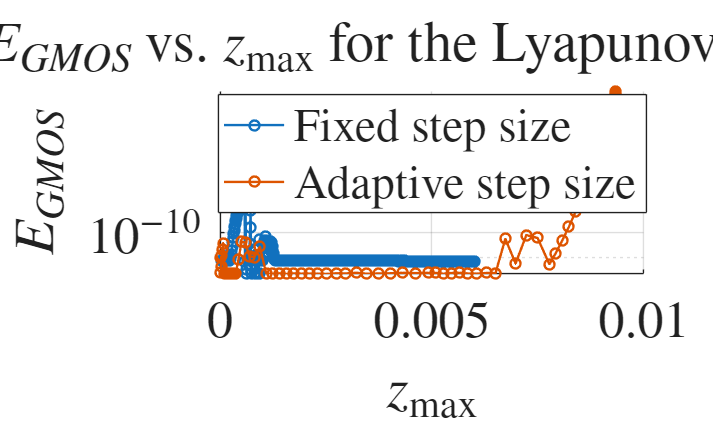


%% -------------------------
% E_GMOS:
% fixed-step vs adaptive-step
% -------------------------
figure;
hold on;

plot(zMax_unref, EGMOS_unref, 'o-', ...
    'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'Fixed step size');

plot(zMax_ref, EGMOS_ref, 'o-', ...
    'LineWidth', 1.2, 'MarkerSize', 5, ...
    'DisplayName', 'Adaptive step size');

set(gca, 'YScale', 'log');
grid on;
xlabel('$z_{\max}$', 'Interpreter', 'latex');
ylabel('$E_{GMOS}$', 'Interpreter', 'latex');
title('$E_{GMOS}$ vs. $z_{\max}$ for the Lyapunov family', ...
    'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'best');